# Gaussian Process Regression Tutorial

By Salvador Gomez and Tanner Harms

On March 21, 2023 for the McKeon Lab group meeting.

## What is Gaussian Process Regression?

Gaussian Process Regression (GPR) represents the use of kernels for regressing a Gaussian process from data.  There is a lot packed into that statement...  To get a better grasp of what is going on in GPR, we will look at three key aspects: 

- Regression

- Gaussian Processes

- Kernel functions and their usefulness to regression problems 

This tutorial will only scratch the surface on GPR and its applications.  If you want to go into more depth, here are some suggested resources.

- [https://gaussianprocess.org/](https://gaussianprocess.org/) - useful resources and a free textbook on Gaussian Process Regression/Bayesian Optimization

- [https://arxiv.org/abs/2009.10862](https://arxiv.org/abs/2009.10862) - An Intuitive Tutorial to Gaussian Processes Regression

Let's jump right in with some regression examples!

### Reminder about linear regression

A fundamental procedure in statistics is building models of phenomena from data.  Some of my favorite quotes about models (of all kinds) are attributed to the statistician George Box:

*"All models are wrong, but some are useful."*

*"Since all models are wrong, the scientist must be alert to what is importantly wrong.  It is inappropriate to be concerned about mice when there are tigers abroad."*

In using the appropriate data to examine a phenomenon, we hope to identify useful trends through the process of regression.  Mathematically, regression is often expressed as


$$Y_i = f(X_i,\beta) + e_i$$


where $(X_i, Y_i)$ are tuples containing the dependent variable and independent variables respectively, $\beta$ is a vector of unknown parameters to be estimated,$f(X_i, \beta)$ is a mapping of the independent variables and parameters to the dependent variable and $e_i$ are errors associated with the data points.  The task of regression is to use the data $(X_i, Y_i)$ to identify $\beta$ by minimizing $e_i$.

In the case of a linear regression, we would use the form


$$Y_i = \beta_0 + \beta_1X_i+e_i$$


Let's do an example in honor of George Box.

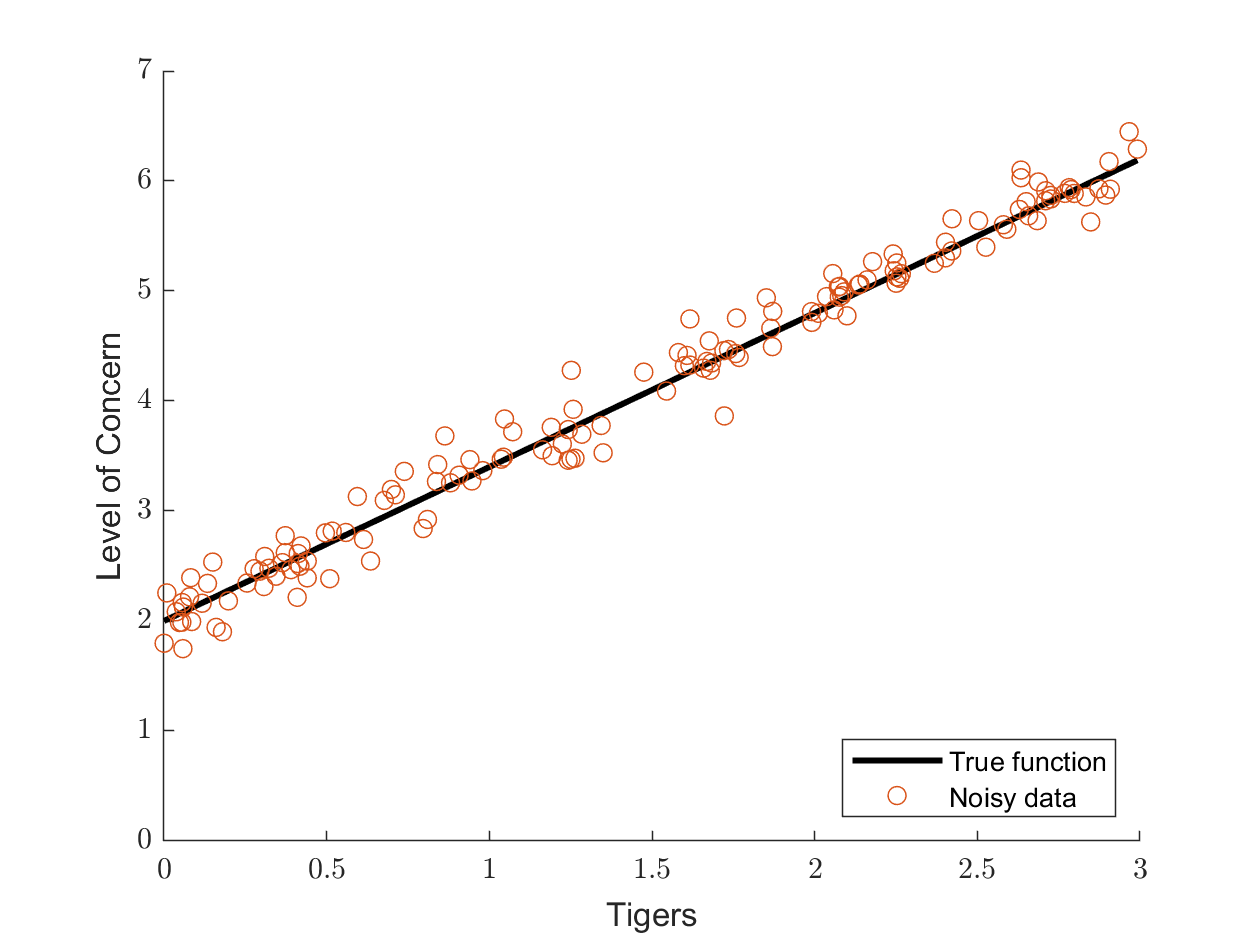

% Let's make a true function that we will sample from.  It will depend on
% betas and the independent variables with noise added.
b0_true = 2;
b1_true = 1.4;
fun = @(b0, b1, X, sigma) b0 + b1*X + normrnd(0,sigma,size(X));

% Now, let's generate some data.
N = 150;                      % Number of data points
Tigers = sort(3*rand([N,1])); % Uniform random from 0 to 3
Mice = 0.2;                   % standard deviation for normal random noise added
HowConcernedIAm       = fun(b0_true, b1_true, Tigers, Mice);  % function with noise
HowConcernedIShouldBe = fun(b0_true, b1_true, Tigers, 0);     % function with no noise

% Plot the data
figure(); hold on; xlim([0,3]); ylim([0,7])
plot(Tigers, HowConcernedIShouldBe, 'k', 'linewidth',2)
scatter(Tigers, HowConcernedIAm)
xlabel('Tigers');  ylabel('Level of Concern')
legend('True function','Noisy data','location','southeast')

Now that we have a function in place, we can do regression to estimate the model.  This is accomplished by minimizing the error term in a least squares sense.  Skipping a lot of steps (see [Ordinary least squares - Wikipedia](https://en.wikipedia.org/wiki/Ordinary_least_squares) for details), you can use the *normal equations *to estimate $\beta$.


$$\hat{\beta} = (\mathbf{X}^\top \mathbf{X})^{-1} \mathbf{X}^\top \mathbf{Y}$$


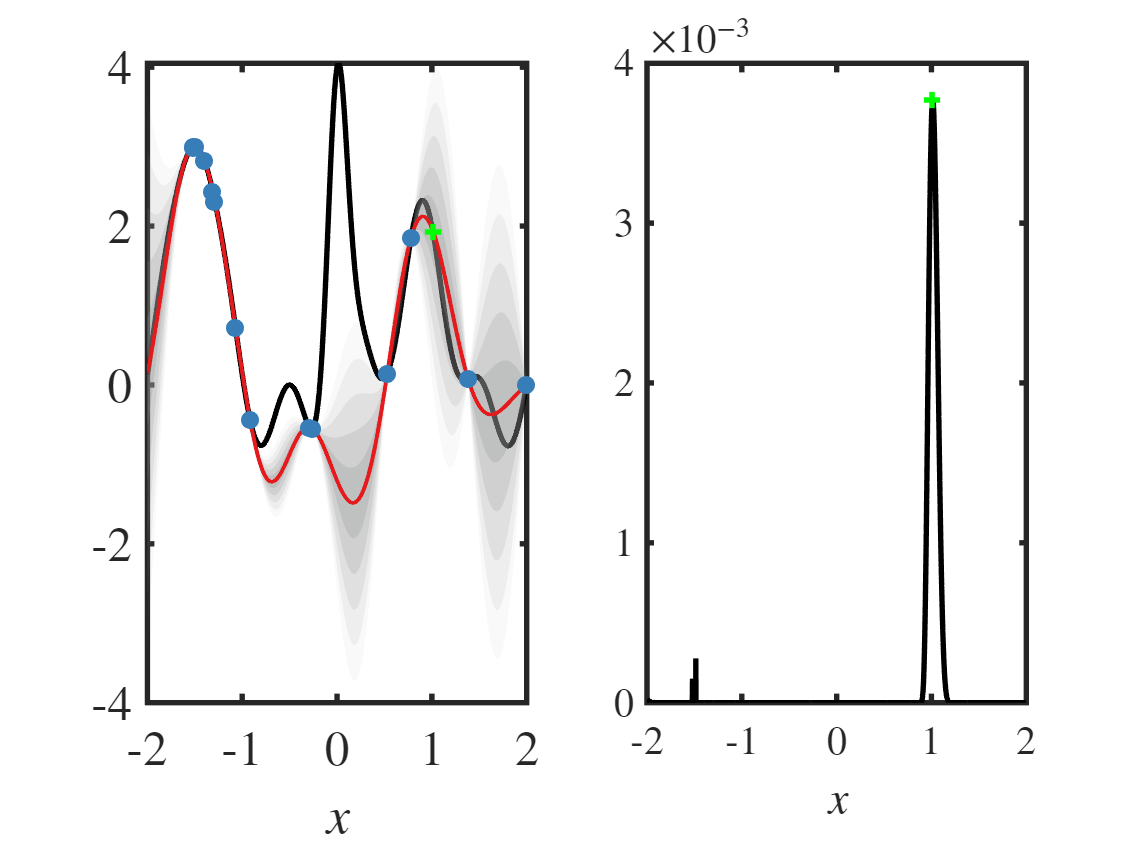

% Let's turn our data into an array.  For the bias term (b0) we say X0 = 1.
X = [ones(size(Tigers)), Tigers];
Y = HowConcernedIAm;

% Let's regress!
b_hat = pinv(X)*Y;

% and plot our new results onto the graph.
regressed_fun = fun(b_hat(1), b_hat(2), Tigers, 0);
plot(Tigers, regressed_fun, '--r', 'linewidth',1.5)
leg = ['Regressed function: b0 = ',num2str(round(b_hat(1),2)),' and b1 = ',num2str(round(b_hat(2),2))];
legend('True function','Noisy data',leg,'location','southeast')

As we see, the regressed function matrches very closely!  However, if we didnt know the form of our model, then we would likely get far worse results.  For example, if we attempted to fit a linear model to data that is actually quadratic, then we would surely get bad results.  

This type of regression is known as parametric regression--we attempt to learn the parameters $\beta$ that are associated with a model family that we expect to see (linear in this case).  Gaussian process regression is a form of non-parametric models, which seeks to fit a general function that describes the expected value of the dependent variable given the independent variable set.  In math-talk, we are trying to solve for $m(x)$ in:


$$\mathbb{E}[Y|X=x]=m(x)$$


In the case of GPR, $m(x)$ is a specific type of function known as a Gaussian process.  We will cover those next.  

### Gaussian Processes

A Gaussian process is a *stochastic process* where each collection of the random values that it generates and all linear combinations thereof are distributed according to a multivariate normal distribution.  **For GP and GPR, the dimension of the multivariate distribution is the size of the state space that regression is occurring over.**  

Let's take a look at a quick example of an uncorrelated gaussian process.  

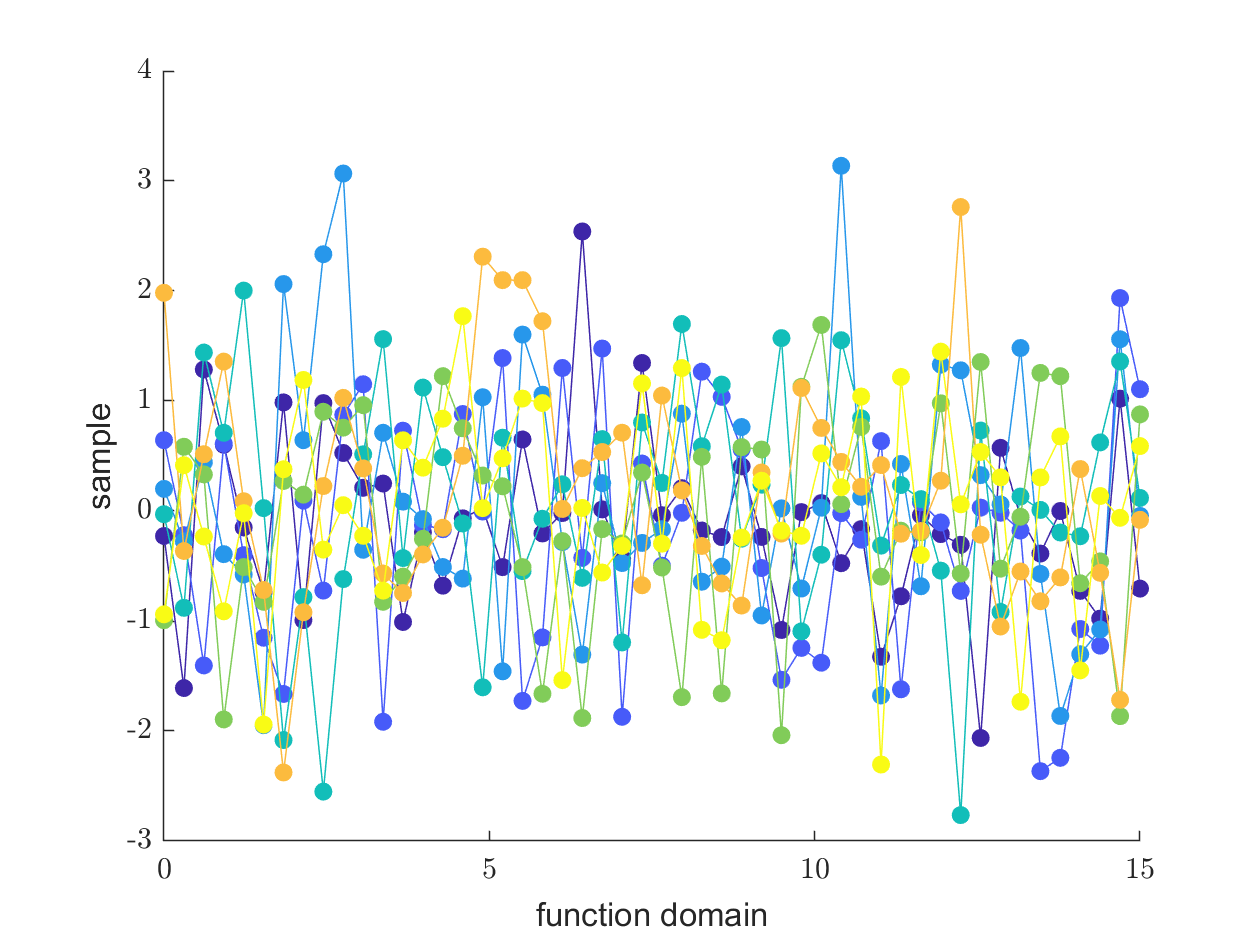

% Select values for the variables:
test_points = 50;
n_samples = 7;
domain = 15;
Xtest = linspace(0,domain,test_points)';

% In this case, we will generate (test_points)-variate normal distributions
% using the identity matrix as the covariance.  This essentially states
% that the points on the state-space are uncorrelated.
mu = zeros([1,test_points]);            % Zero mean
cov = eye(test_points);                 % Uncorrelated
samples = mvnrnd(mu, cov, n_samples);

% Plot the results
col = parula(n_samples);
figure(); hold on
for i=1:n_samples
    plot(Xtest, samples(i,:), 'color', col(i,:))
    scatter(Xtest, samples(i,:), 'filled', 'MarkerFaceColor', col(i,:))
end
xlabel('function domain');  ylabel('sample')

Because each of the test points is uncorrelated with all of the others, the result above appears to be random noise--although, a brief inspection verifies that the data is normally distributed about the mean with unit standard deviation.  By defining covariance matrix in a smart way, we can enforce certain behavior in our random variables.  

The function that we use to design our covariance matrix is called the **kernel function**, and it is defined as

$k(x,x') = f(x, x', p)$,

where $p$ are parameters that influence the kernel function's behavior.  Using the kernel function, the covariance (or kernel) matrix is defined according to


$$K_{ij} = k(x_i, x_j)$$


As we shall see later in the tutorial, the choice of kernel function is extrememly important to the character of the regressions that are done.  However, it is quite common to start with a Gaussian (aka. radial basis function or squared-exponential) kernel.  This is defined according to the relation

$k_{SE} (x,x') = \sigma^2 \exp\left(-\frac{(x-x')^2}{2l^2}\right)$,

where $l$ is a lengthscale that determins the wavelength of the output and $\sigma^2$ is the variance of the output.  We can demonstrate this again in the code:

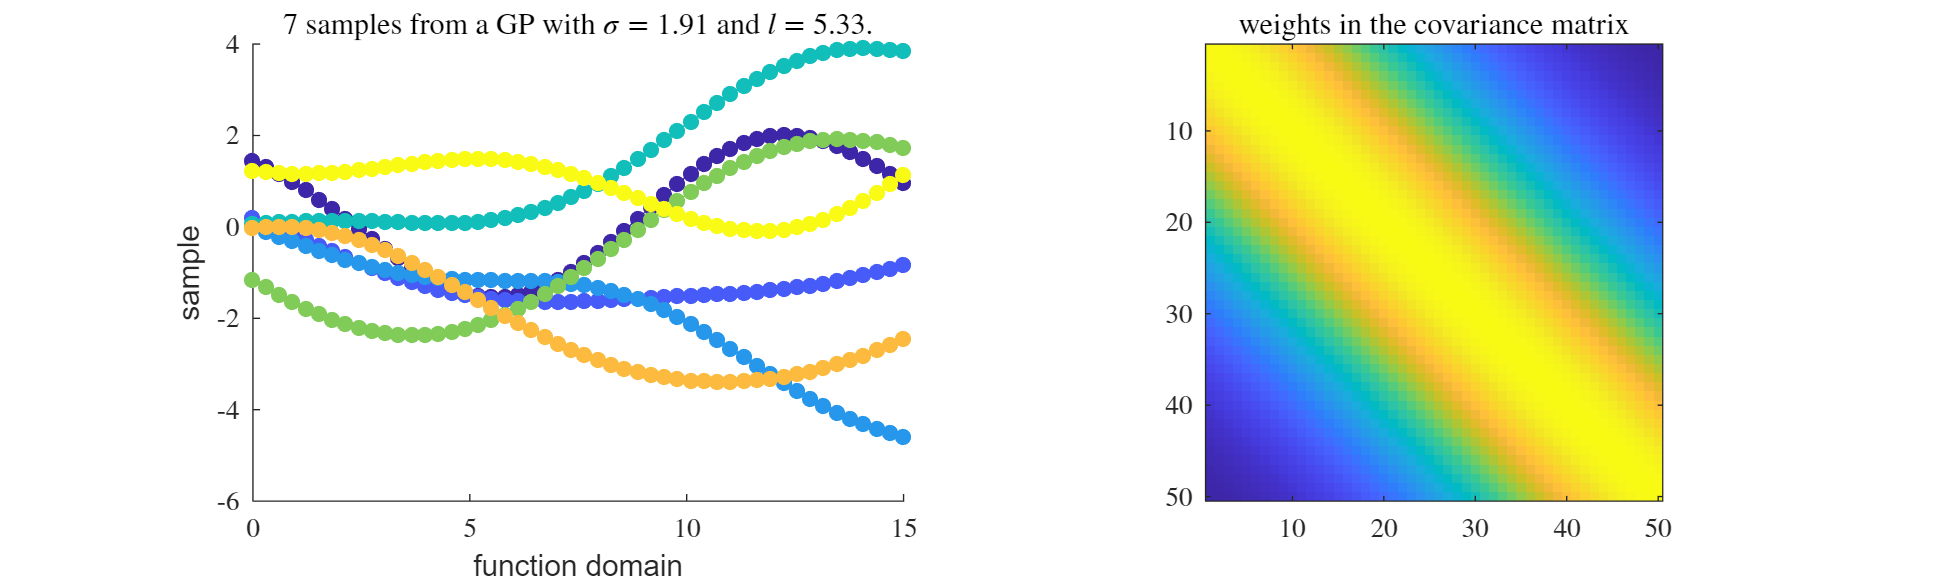

% First, let's define the gaussian kernel function.  We will use the same
% environment parameters from the previous code block.
kernel_se = @(x1,x2,s,l) s.^2.*exp(-(x1-x2).^2./(2*l.^2));

% Let's use some variables to define our model parameters.
l     = 5.33;
sigma = 1.91;

% Now, to calculate the covariance matrix, we will compute the kernel function for
% every pair of data.
cov = zeros(test_points, test_points);
for i = 1:test_points
    for j = 1:test_points
        cov(i,j) = kernel_se(Xtest(i),Xtest(j),sigma,l);
    end
end

% Now, we will re-plot the functions as before to see how kernelizing the
% covariance influences them.
samples = mvnrnd(mu, cov, n_samples);

figure('units','inches','position',[1,1,10,3])
subplot(1,2,1); hold on   % Plot the samples
for i=1:n_samples
    plot(Xtest, samples(i,:), 'color', col(i,:))
    scatter(Xtest, samples(i,:), 'filled', 'MarkerFaceColor', col(i,:))
end
title([num2str(n_samples),' samples from a GP with $\sigma=', num2str(sigma), '$ and $l=', num2str(l),'$.'],'interpreter','latex')
xlabel('function domain');  ylabel('sample')

subplot(1,2,2)            % Plot the covariance matrix
imagesc(cov)
title('weights in the covariance matrix','interpreter','latex')
axis square

## Gaussian Process Regression

Now, the task of Gaussian process regression is to fit the mean and covariance using known data within the regression domain.  Referring back to the non-parametric regression remodel from a few sections ago, we are try to solve for some function 

$\mathbb{E}[Y|X=x]=f(x)$,

where

$f(x) \sim \mathcal{N}(Y|\mu, K)$,

and in terms of the Gaussian Process, we could define this as

$f(x) \sim \mathcal{GP}(m(x), k(x,x'))$,

where 


$$m(x)=\mathbb{E}[f(x)]$$


$k(x,x') = \mathbb{E}[(f(x)-m(x))(f(x')-m(x'))]$. 

In other words, the prior assumption of the regression is that it is a Gaussian process governed by mean $\mu$ and covariance $K$.  Therefore, **in GPR it is the mean and covariance that are identified**.  This is advantageous since, unlike the parametric model from before, we learn not just the most likely function, but an entire family of functions that fit the data.  We will have built-in confidence intervals on the data which are determined by the regression.   

### Kernel Methods for Regression

It is helpful now to discuss Kernel methods for regression.  The model that we considered in the section on linear regression is limited to identifying only linear functions.  Real life, however, is nonlinear.  In order to regress nonlinear data, adjustments must be made to the regression problem.  One way to do this is to elevate your data into a feature-space $\phi(x)$ which contains various functions of the input data.  For example, a polynomial library looks like this.  


$$\phi(x) = [1, x, x^2, x^3, x^4, \dots]$$


and would come with weights $\beta_i$ associated with each element.  By regressing these weights through ordinary least-squares on the feature space, a nonlinear function of the feature variables can be identified.  For those familiar with Steve Brunton's work, this is partly how SINDy works.  

One of the big problems with doing regressions on a library (indeed, a challenge that SINDy had when it was first developed) is that computing the feature space for all of the input data can be intractably expensive in terms of computation and data storage.  Especially considering the fact that the feature-space may be infinite-dimensional.  However, if you work through the linear regression minimization problem using the feature-space with $\mathbf{\Phi}$ defined as $\Phi_{ij} = \phi_{j}(x_i)$, then we see that the matrix $K = \mathbf{\Phi} \mathbf{\Phi}^\top$ appears frequently.  Each entry of $K$ represents an inner product of the feature variables such that $K_{mn} = \phi(x_m)^\top \phi(x_n) = k(x_m, x_n)$.  Using this result, the regressed function in the feature space can be represented as 

$f(x) = \beta^\top \phi(x) =K_*(X)^\top K^{-1} Y$,

where $K_*(X) = k(x_n, x)$ is the kernel function evaluated between the data points and all of the points on the sampled domain.  

The important feature of the above discussion is the *kernel trick, *which implies that **the feature-space regression can be evaluated without ever actually computing the data in the feature space**.  All that is needed is a valid inner-product over the feature space.  As it turns out, **valid kernels all result in a symmetric, positive semi-definite kernel matrix, **$K$.

### Kernel Methods in GPR

In GPR, we enforce the prior distribution of the weights $\beta$ to be isotropic Gaussian of the form


$$\beta \sim \mathcal{N}(w|0,\alpha^{-1} I)$$


with $\alpha$ the precision.  Then, since $Y = \mathbf{\Phi}\beta$, the mean and covariance are given by


$$\mathbb{E}[Y] = \mathbf{\Phi} \mathbb{E}[\beta] = 0$$



$$cov[Y] =  \mathbf{\Phi} \mathbb{E}[\beta \beta^\top] \mathbf{\Phi}^\top = \frac{1}{\alpha}\mathbf{\Phi \Phi}^\top = K$$
 

Taking noise into account such that $Y = f(X)+\epsilon$ with $\epsilon\sim \mathcal{N}(0,\beta^{-1}I)$, we seek to find the distribution $p(Y_{N+1}) =  \mathcal{N}(Y_{N+1}|0, C_{N+1})$, where $C_{mn} = k(x_m, x_n) + \beta^{-1}\delta_{mn}$ is the covariance matrix with the data noise incorporated.  In this model, the regressed covariance matrix has the form


$$C_{N+1}=\pmatrix{ C_N & K_* \cr K_*^\top & K_{**}}$$


Using this to find the conditional distribution $p(Y_{n+1}|Y)$ will uield a Gaussian distribution with mean and covariance given by


$$m(X_{N+1}) = K_*^\top C_N^{-1} Y$$


$\Sigma(X_{N+1}) = K_{**}-K_*^\top C_N^{-1} K_*$.

For details on this process, see Bishop, chapter 2.  

Applying these equations to all of the data points in the regression domain yields result we have been looking for.  Let's consider an example:

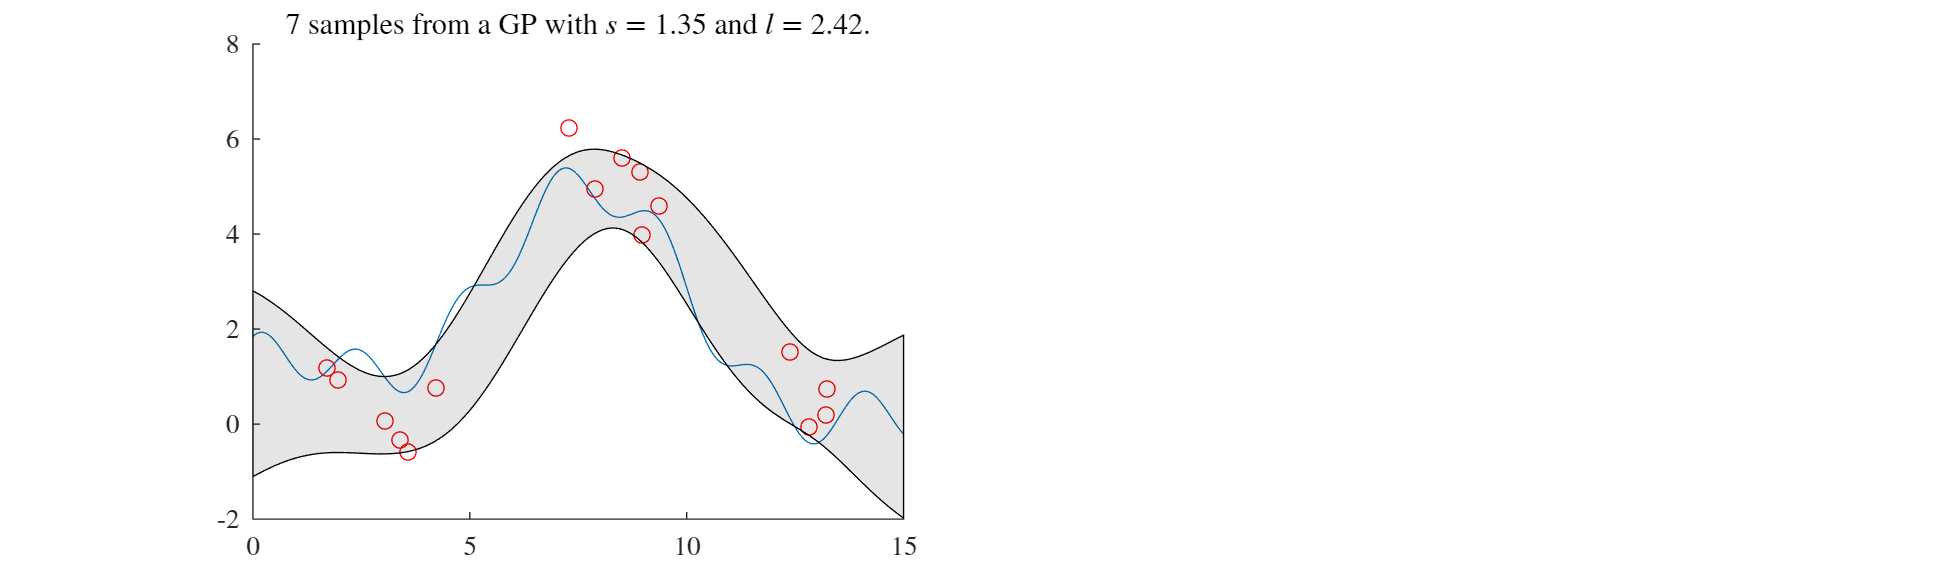

% Let's begin with our variables
N    = 16;    % Observation points
n    = 293;   % test points
m    = 10;    % number of sample functions
beta = 0.897;  % noise variance
r    = 15;                            % range of the domain

% Make a vector of the test domain
Xtest = linspace(0,r,n)';

% Sample observation points
X_rand = r*rand([N,1]);     % Random sampling of the domain
X_unif = linspace(0,r,N)';  % Uniform sampling of the domain
X = X_rand;

% random test function to work with.
test_fun = @(x) 1.5*sin(2+0.75*x) + 0.5*sin(1.3+2.7*x) + x - 0.07*x.^2;   % Just an arbitrary sum of sinusoids
y = test_fun(X)+ beta*randn(size(X));                     % Data points with noise added

% Evaluate the kernel at the data points.
l = 2.42;   % Influences viable wavelengths
s = 1.35;   % Influences output variance

% Evaluate the covariance at the data points
K = covariance_matrix(X,X,s,l,kernel_se);

% Evaluate the covariance between the data and the test points
K_star = covariance_matrix(X,Xtest,s,l,kernel_se);

% Evaluate the covariance at the test points only
K_starstar = covariance_matrix(Xtest,Xtest,s,l,kernel_se);

% Compute the mean and covariance.
mu = K_star'/(K + beta*eye(N))*y;
cov = K_starstar - K_star'/(K + beta*eye(N))*K_star;

% Compute the variance at each test point
stdv = sqrt(diag(cov));

samples = mvnrnd(mu, cov, m);

% Generate a figure to visualize the distributions
figure('units','inches','position',[1,1,10,3])
subplot(1,2,1); hold on   % Plot the samples
plot(Xtest,test_fun(Xtest))
plot(X,y,'or')
fill([Xtest', fliplr(Xtest')], [mu'+2*stdv', fliplr(mu'-2*stdv')],'black','FaceAlpha',0.1)
title([num2str(n_samples),' samples from a GP with $s=', num2str(s), '$ and $l=', num2str(l),'$.'],'interpreter','latex')

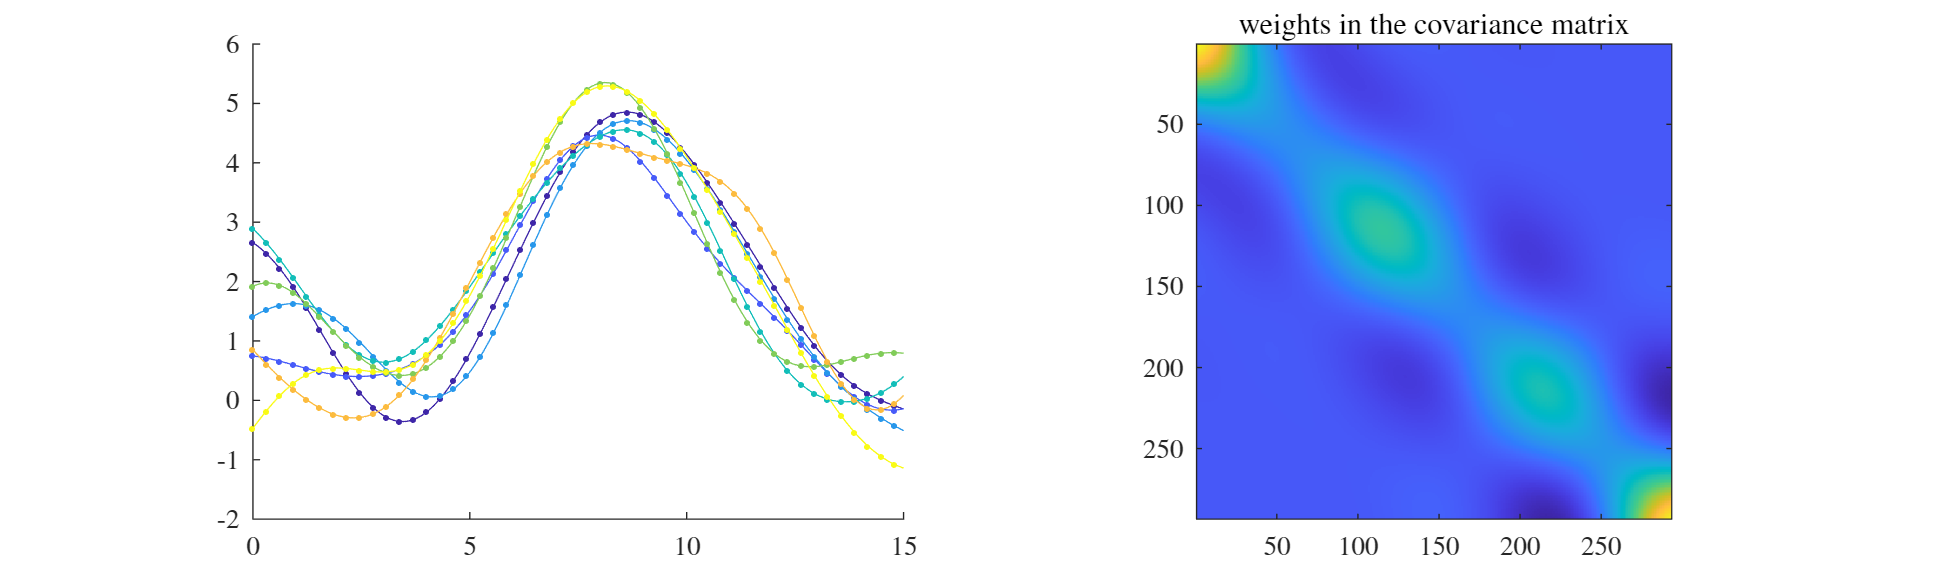


% Generate a figure to visualize samples on the distribution
figure('units','inches','position',[1,1,10,3])
col = parula(n_samples);
subplot(1,2,1); hold on   % Plot the samples
for i=1:n_samples
    plot(Xtest, samples(i,:), 'color', col(i,:))
    scatter(Xtest(1:6:end), samples(i,1:6:end), 5, 'filled', 'MarkerFaceColor', col(i,:))
end
subplot(1,2,2)            % Plot the covariance matrix
imagesc(cov)
title('weights in the covariance matrix','interpreter','latex')
axis square

As you play with this code, what do you notice?  Here are some questions to think about:

- What parameters seem to do the best job?

- How do the characteristics of the function influence the performance of the regression?

- What does the structure of the covariance matrix tell you about the data?

- What might be some disadvantages of using Kernel regression/GPR instead of standard regression?

## Choice of Kernel Functions

- Discuss choices of the hyperparameters in RBF (the std, amplitude, and regularizer)

- Discuss Kernel function properties

- Discuss common Kernel functions (RBF, Matern, Periodic, etc.)

In general, a **kernel**, is any integrable function $K : \mathbb{R}^{d}\times \mathbb{R}^{d}\rightarrow\mathbb{C}$. A kernel is **positive definite **if it satisfies the condition 


$$\langle h,K h \rangle = \int_{\mathbb{R}^{d}\times \mathbb{R}^{d}} h(\mathbf{x})^{*}K(\mathbf{x},\mathbf{y})h(\mathbf{y})d\mathbf{x}d\mathbf{y}\ge 0$$


for any *integrable* function $h:\mathbb{R}^{d}\rightarrow \mathbb{C}$. From this integral equation, it can be shown that $K$is Hermitian since $K(\mathbf{x},\mathbf{y}) = K(\mathbf{y},\mathbf{x})^{*}$. As mentioned earlier, we are interested in covariances, so we'll focus on $K : \mathbb{R}^{d}\times \mathbb{R}^{d}\rightarrow\mathbb{R}$, which are symmetric operators, from here on out. Given a set of vectors $\{ \mathbf{x}_{1},\dots,\mathbf{x}_{n}\}$, we can define the associated **kernel matrix**, $\mathbf{K}\in\mathbb{R}^{n}\times\mathbb{R}$ with entries $K_{ij} = K(\mathbf{x}_{i},\mathbf{x}_{j})$. This matrix is positive definite as for any $\mathbf{a}\in\mathbb{R}^{n}$, $\mathbf{a}^{T}\mathbf{K}\mathbf{a}\ge 0$. This can be shown by using $h = \sum_{j=1}^{n}a_{i}\delta(\mathbf{x}-\mathbf{x}_{j})$ in the integral equation. 

**Examples of kernel functions**

There are infinitely many kernel functions one can choose. Here are a few kernel functions that are often seen in several applications: 

- *Inner product kernel *$K(\mathbf{x},\mathbf{y}) = \langle\mathbf{x},\mathbf{y}\rangle$

- *Correlation kernel *$K(\mathbf{x},\mathbf{y}) = \frac{\langle\mathbf{x},\mathbf{y}\rangle}{\|\mathbf{x}\|\|\mathbf{y}\|}$

- *Radial basis function *$K(\mathbf{x},\mathbf{y}) = \mu^{2}\exp(-\|\mathbf{x}-\mathbf{y}\|^{2}/(2 \sigma^{2})$

Since we are interested in the distance between points in space, GPR focuses a lot on translation invariant kernels of the form


$$K(\mathbf{x},\mathbf{y}) = f(\mathbf{x} - \mathbf{y})$$


where $f:\mathbb{R}^{d}\rightarrow\mathbb{R}$. Because of symmetry and positive-definiteness of $K$, $f(-\mathbf{x}) = f(\mathbf{x})$, $f(\mathbf{x}) \le f(\mathbf{0})$, and $f(\mathbf{0})\gt 0$. The radial basis function is an exaple of these. 

We can define a few common kernel functions below:

set(groot, 'defaultAxesTickLabelInterpreter','latex')
%kernel functions you can choose:
kernel_fun1 = @(x1,x2,s,l) s.^2.*(1 + sqrt(3)./l.*abs(x1-x2)).*exp(-sqrt(3)/l*abs(x1-x2)); %matern 3/2
kernel_fun2 = @(x1,x2,s,l) s.^2.*(exp(-abs(x1-x2)./l)); %matern 1/2
kernel_fun3 = @(x1,x2,s,l) s.^2.*exp(-(x1-x2).^2./(2*l.^2)); %radial basis function
kernel_fun4 = @(x1,x2,s,l) s.^2 + (x1 - l).*(x2 - l); %linear basis function
kernel_fun5 = @(x1,x2,s,l,Np) s.^2.*exp(-sin(pi*abs(x1-x2)*Np).^2./(2*l.^2)); %periodic kernel (define Np, number of periods you expect)
%note that you can define many more!

Note that this list is not exhaustive, there are (infinitely) many more options for kernel functions as we'll see later. 

Making the parameter $l$ in the RBF smaller makes points that are further apart less correlated and increased *l *makes points that are further apart more correlated. You can think of $l$ as a length scale. 

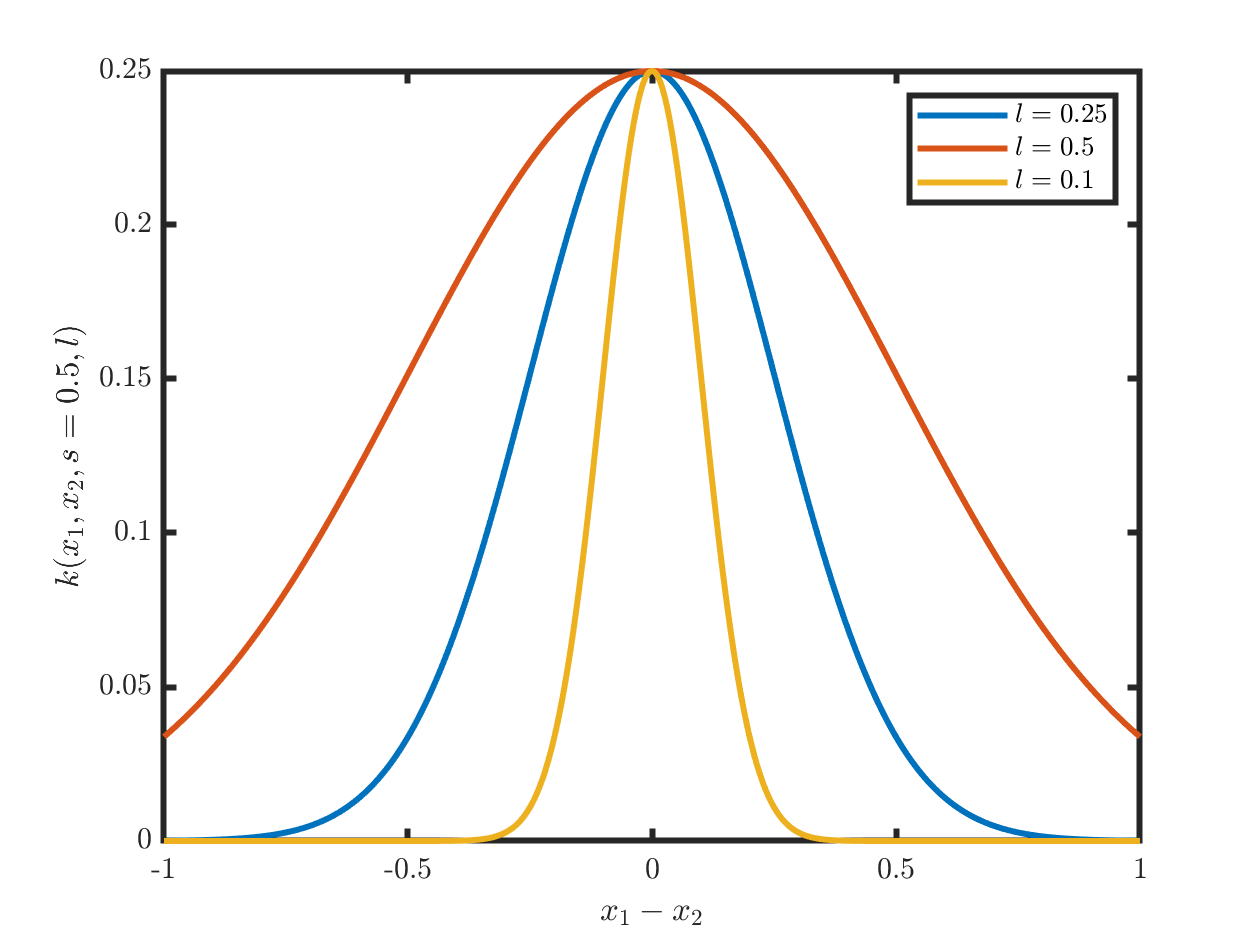

%now we'll show what happens when you vary the parameter l in the Radial Basis Function
x = linspace(-1,1,1000);
s = .5; l1 = .25; l2 = .5; l3 = .1;
figure()
plot(x,kernel_fun3(x,0,s,l1),'LineWidth',2); hold on;
plot(x,kernel_fun3(x,0,s,l2),'LineWidth',2); hold on;
plot(x,kernel_fun3(x,0,s,l3),'LineWidth',2); hold on;
xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l)$'],'Interpreter','latex');
legend({['$l = ',num2str(l1),'$'],['$l = ',num2str(l2),'$'],['$l = ',num2str(l3),'$']},'Interpreter','latex');
set(gca,'linewidth',2); hold off;

The Matern kernels adds *pointyness* to the radial basis function. This allows them to approximate functions that have sharp features without having to change the value of *l. *This *pointyness *increases the correlation of points that are close together while maintaining the correlation of the points that are further apart. You can think of this as having the benefits of a large *l *in getting global information (points far apart) while having the benefits of a small *l *in weighing local information (points close together). 

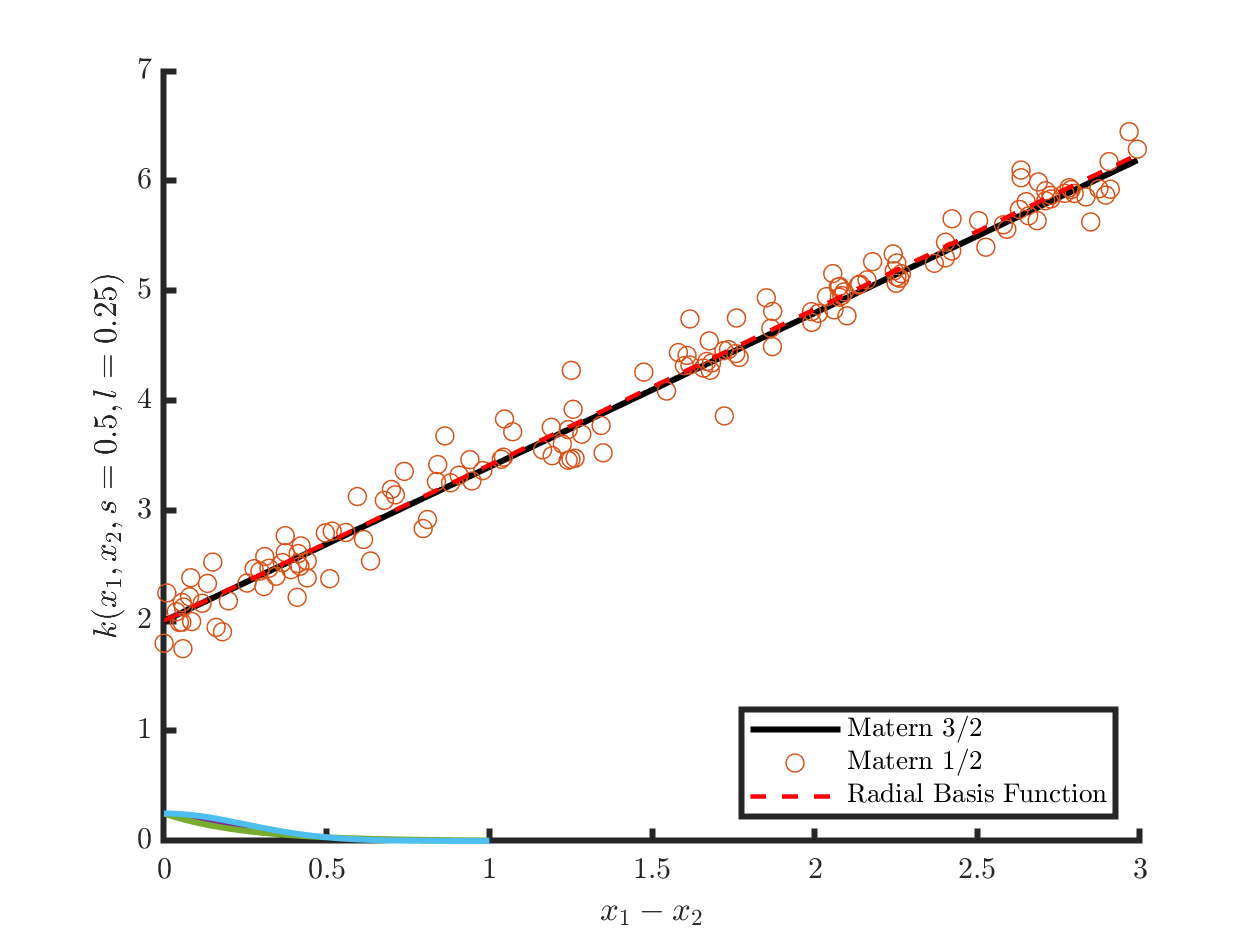

%plotting the kernel functions:
x = linspace(-1,1,1000);
s = .5; l = .25;
figure(1)
plot(x,kernel_fun1(x,0,s,l),'LineWidth',2); hold on;
plot(x,kernel_fun2(x,0,s,l),'LineWidth',2); hold on;
plot(x,kernel_fun3(x,0,s,l),'LineWidth',2); hold on;
xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l = ',num2str(l),')$'],'Interpreter','latex');
legend({'Matern $3/2$','Matern $1/2$','Radial Basis Function'},'Interpreter','latex');
set(gca,'linewidth',2); hold off;

The periodic kernel is useful when your signal has known periodicity (Np). 

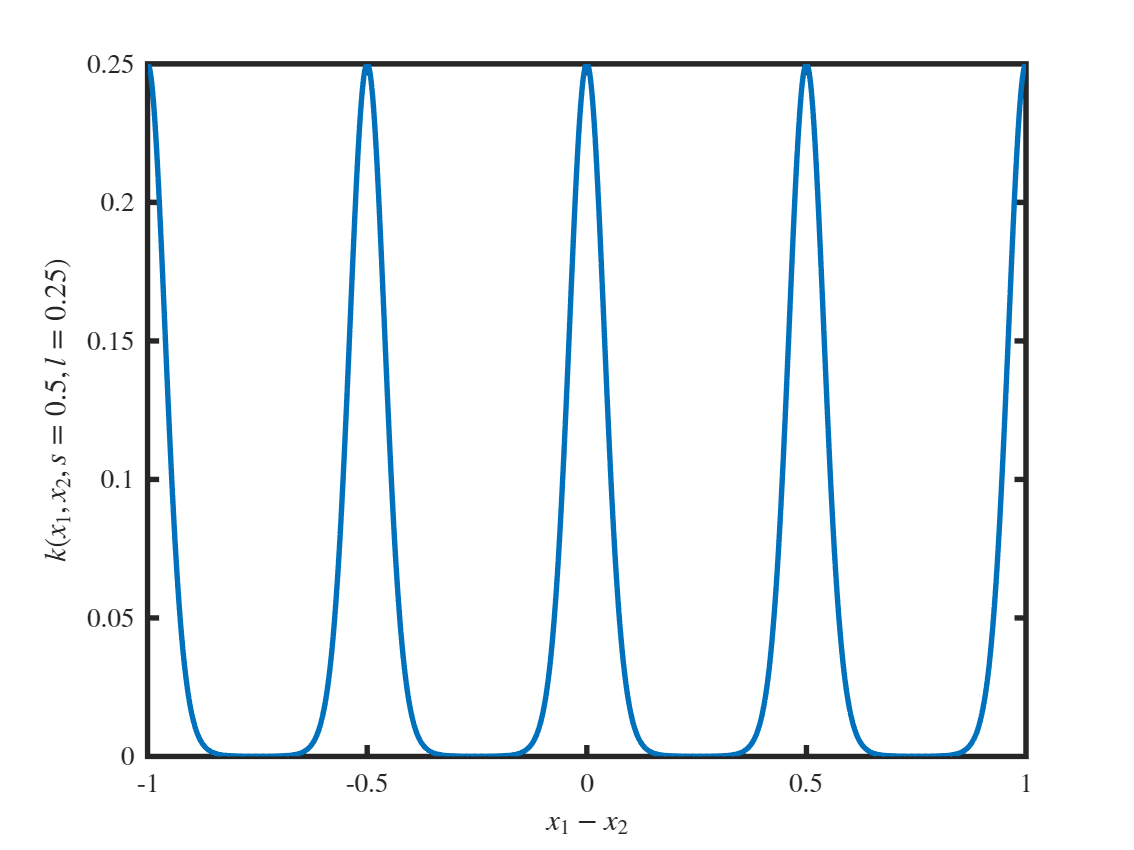

%plotting the periodic kernel functions:
x = linspace(-1,1,1000);
s = .5; l = .25;
figure(1)
plot(x,kernel_fun5(x,0,s,l,2),'LineWidth',2); hold on;
xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l = ',num2str(l),')$'],'Interpreter','latex');
set(gca,'linewidth',2); hold off;

If these kernel functions do not suffice, you can build your own kernel functions by multiplying kernel functions together or adding them together. 

- For any positive $a$ and kernel function $K$, $aK$ is also a kernel

- For any kernel functions $K_{1}$ and $K_{2}$, their sum $K_{1}+K_{2}$ is also a kernel

- For any kernel functions $K_{1}$ and $K_{2}$, their product $K_{1}K_{2}$ is also a kernel

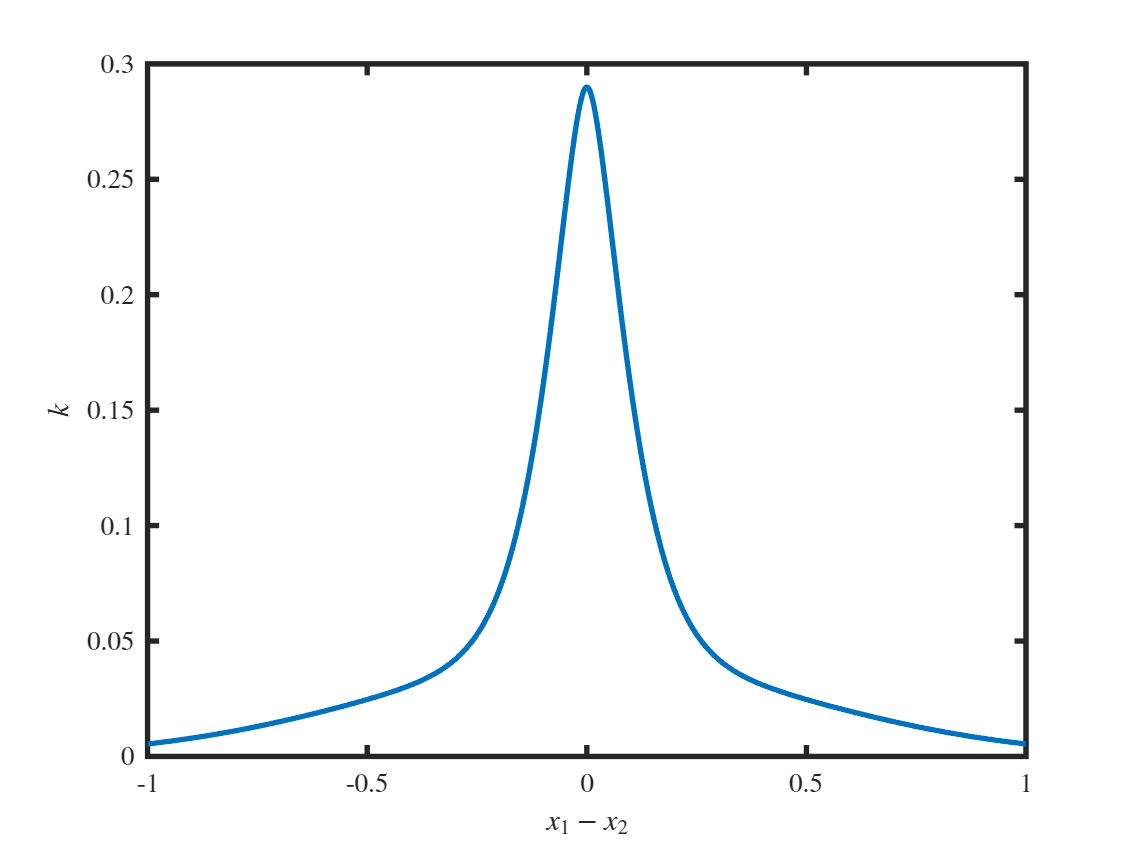

%example:
k_add = @(x1,x2,s,l,p,q) kernel_fun1(x1,x2,s,l) + kernel_fun3(x1,x2,p,q);
plot(x,k_add(x,0,.5,.1,.2,.5),'LineWidth',2)
xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k$'],'Interpreter','latex');
set(gca,'linewidth',2); hold off;

%create your own kernels:


You can find more examples of kernels in the following: https://www.cs.toronto.edu/~duvenaud/cookbook/

## Kernel functions in practice: 

For the given parameters, the RBF does a lot better at approximating the sinusoidal input. However, when the function has an absolute value the Matern kernel does a better job at approximating the function. 

In the following example, **vary the value of a **to increase the amplitude of the absolute value function. 

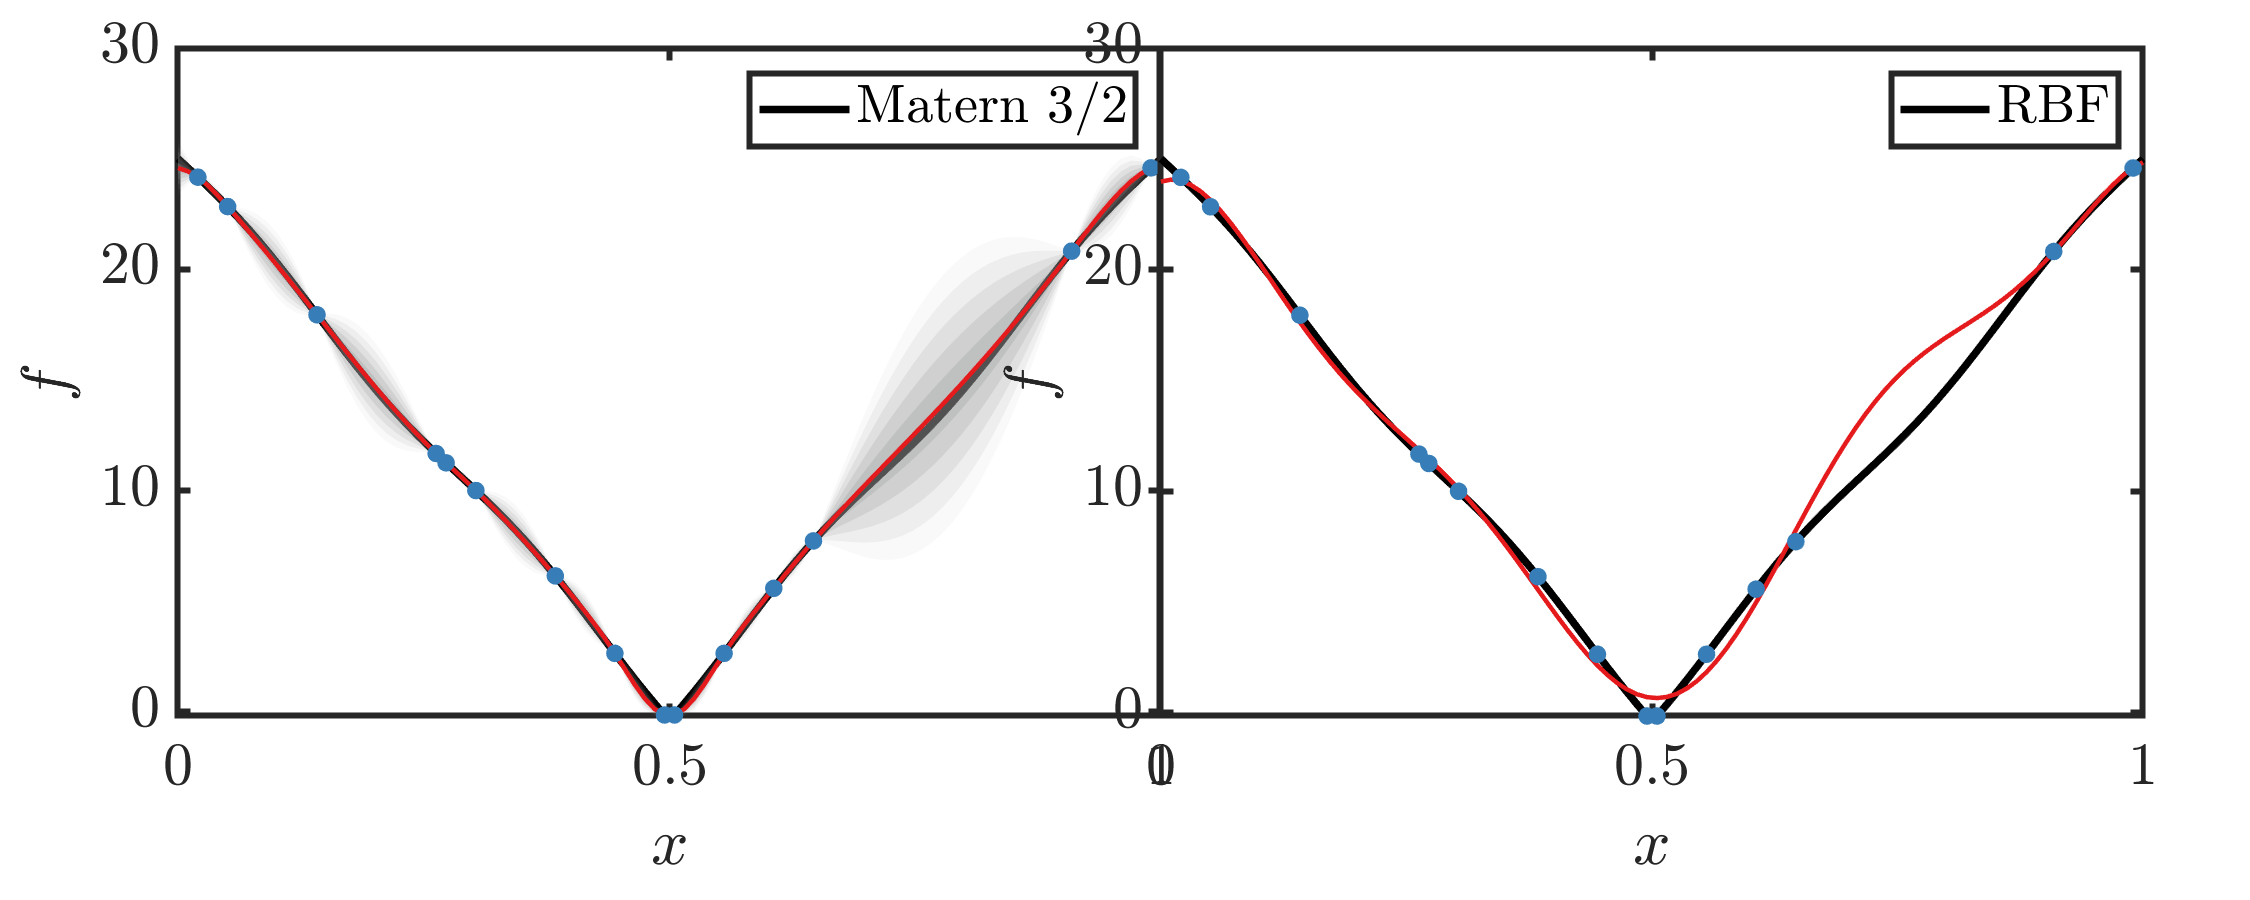

clear x_data y_data m_data
a          = 10;
f          = @(x) .4*(sin(7*pi*x)) + (a*abs(5*(x-.5))); %function we want to model
x          = linspace(0,1,100)'; %points we'll use
ftrue      = f(x);
rng(1)%seed we'll use
ii         = randperm(length(x))'; Num_Samples = 15;
%ii         = round(linspace(1,100,15))';
s = 4; l = .3; i = 0;  %in practice, a robust code optimizes the choice os s and l and i
figure()
tiledlayout(1,2,'TileSpacing','none','Padding',"compact");
nexttile
%get data for the GPR:
x0                     = x(ii(1:Num_Samples,1));
eval                   = f(x0); %evaluate at sample point
x_data                 = x0;
y_data                 = (eval);
m_data                 = [y_data];
plot(x,ftrue,'LineWidth',2.5,'color','k'); hold on; %plot the actual data
[mean_m, cov_m, var_m] = plot_results(x_data,m_data,x,s,l,i,kernel_fun1,0); %compute the GPR and plot
xlabel('$x$','Interpreter','latex'); ylabel('$f$','Interpreter','latex');
legend('Matern 3/2','interpreter','latex')
set(gca,'LineWidth',2,'FontSize',20)
nexttile
%get data for the GPR:
x0                     = x(ii(1:Num_Samples));
eval                   = f(x0); %evaluate at sample point
x_data                 = x0;
y_data                 = (eval);
m_data                 = [y_data];
plot(x,ftrue,'LineWidth',2.5,'color','k'); hold on; %plot the actual data
[mean_m, cov_m, var_m] = plot_results(x_data,m_data,x,s,l,i,kernel_fun3,0); %compute the GPR and plot
xlabel('$x$','Interpreter','latex'); ylabel('$f$','Interpreter','latex');
set(gca,'LineWidth',2,'FontSize',20)
legend('RBF','interpreter','latex')
set(gcf,'position',[100,100,1000,400])

## **Optimal choice of parameters: **

The main idea for parameter optimization is maximizing the log-marginal likelihood defined as 


$$\log(p(\mathbf{y}\vert \mathbf{x},\mathbf{\theta}) = -\frac{1}{2}\left[\mathbf{y}^{T}\left(K(\mathbf{x},\mathbf{x};s,l)+i^{2}I\right)^{-1}\mathbf{y} + \log(\det(K(\mathbf{x},\mathbf{x};s,l)+i^{2}I)) + n\log(2\pi)\right]$$


where $\mathbf{y}$ are the observations, $\mathbf{x}$ are the samples, $s,l,$ and $i$ are the amplitude, lengthscale, and added noise, respectively. The first term is the data fitting term, if $\left(K(\mathbf{x},\mathbf{x};s,l)+i^{2}I\right)^{-1}\mathbf{y}$ approximates $\mathbf{y}$ well then it'll be maximized. The second term only depends on the kernel function, and its parameters and can be thought of as the model complexity. Finally the third term is a normalization, where $n$ the number of samples used. 

Maximizing this function gives you the optimal parameters $\mathbf{\theta}^{^{\star}}$ s.t. 

   $\mathbf{\theta}^{^{\star}}(\mathbf{y},\mathbf{x}) = \textrm{armgax}_{\theta}(p(\mathbf{y}\vert\mathbf{x},\mathbf{\theta})$.

Note that the optimal paramters are a function of the dataset (and the kernel used)! Here we will demonstrate an example with the radial basis function:

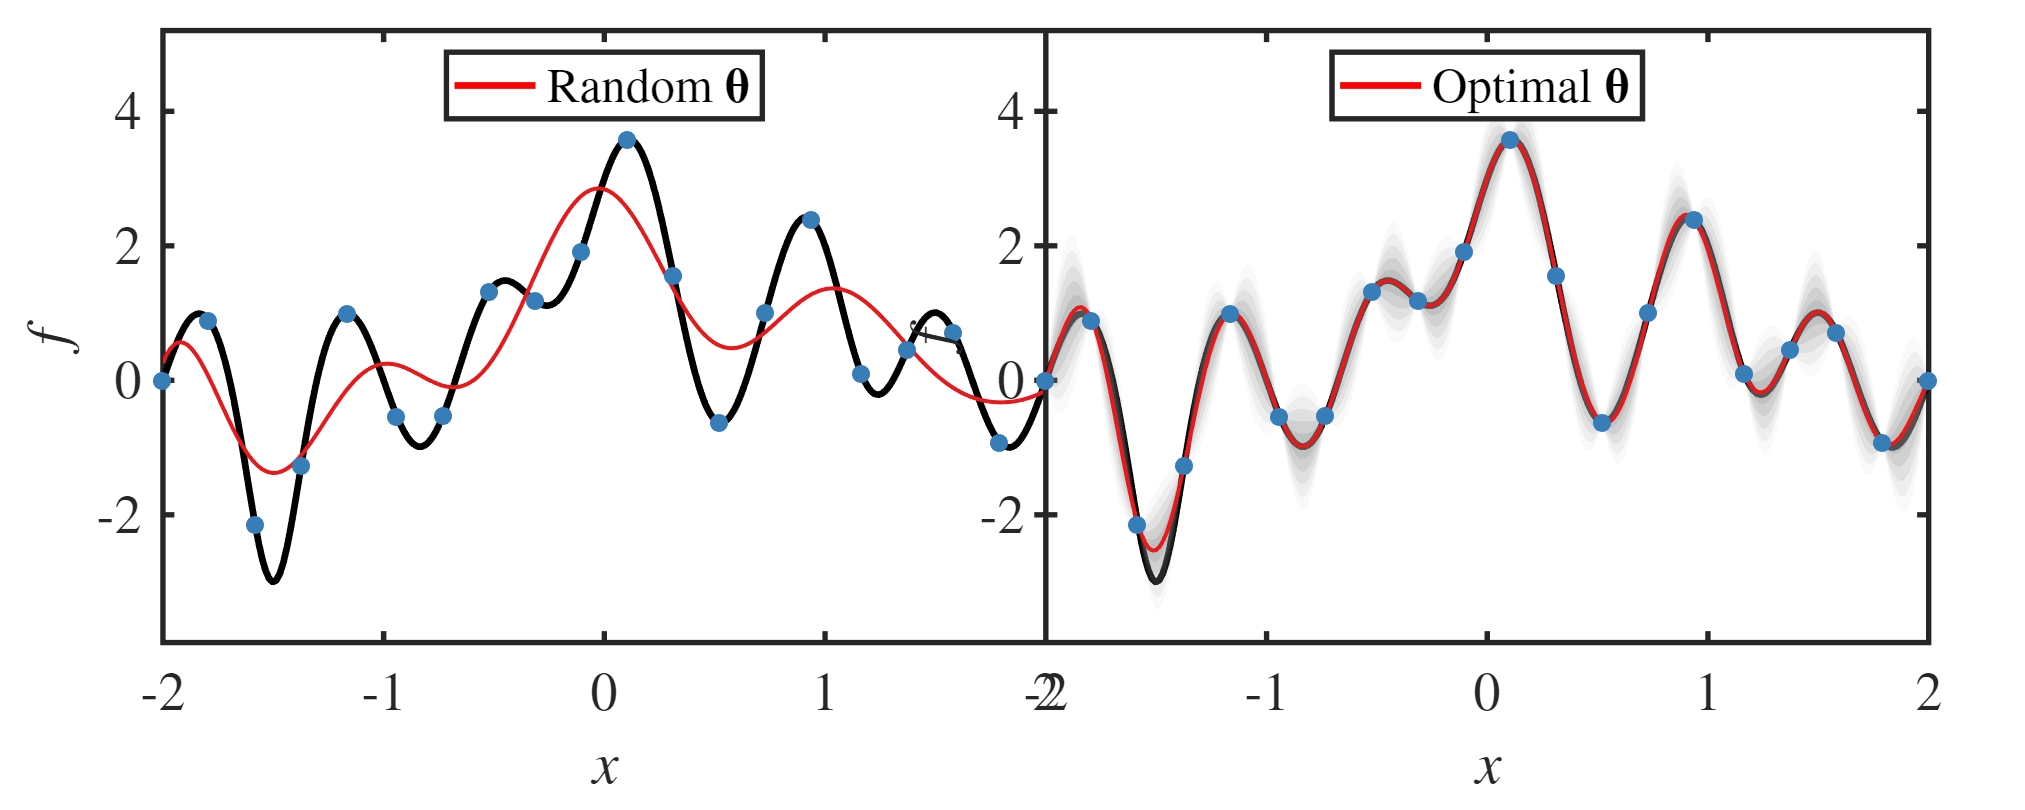

%%
clear x_data y_data m_data
a          = 0;
%f          = @(x) .4*(sin(2*pi*x)) + 1*abs(x-.5); %function we want to model
f          = @(x) 3*exp(-(x).^2/(2*.25^2)) + 2*exp(-(x-1).^2/(2*.15^2)) - 2*exp(-(x+1.5).^2/(2*.1^2)) + sin(3*pi*x);
x          = linspace(-2,2,250)'; %points we'll use
ftrue      = f(x);
rng(1)%seed we'll use
Num_Samples = 20; ii = round(linspace(1,length(x),Num_Samples));
%ii = randperm(length(x));
s0 = rand(1); l0 = rand(1) ; i0 = 10^-10;
%get data for the GPR:
x0      = x(ii(1:Num_Samples));
eval    = f(x0); %evaluate at sample point
x_data  = x0;
y_data  = (eval);
kernel_fun = kernel_fun3; %using the radial basis function
%create the function to optimize (the log marginal likelihood)
fun = @(X) -(1)*(log_marginal_likelihood(X(1),X(2),-10,kernel_fun,x_data,y_data));
%perform the optimization
options = optimoptions('fminunc','Display','off');
Xs = fminunc(fun,[1,-1],options); Xs(3) = -10; %note we are not optimizing over i, assuming perfect measurements
Xs = exp(Xs); %the optimization was done in log space.
%maybe the optimization could be done in a better way that incorporates
%the derivative information of the log-marginal likelihood. Not explored here
s   = Xs(1); l = Xs(2); i = Xs(3);
%s   = Xs(1); l = Xs(2); i = 0;
figure()
tiledlayout(1,2,'TileSpacing','none','Padding',"compact");
nexttile
plot(x,ftrue,'LineWidth',2.5,'color','r'); hold on
plot(x,ftrue,'LineWidth',2.5,'color','k'); ylim1 = ylim; hold on; %plot the actual data
[mean_m, cov_m, var_m] = plot_results(x_data,y_data,x,s0,l0,i0,kernel_fun,0); %compute the GPR and plot
xlabel('$x$','Interpreter','latex'); ylabel('$f$','Interpreter','latex'); ylim(1.3*ylim1)
legend('Random $\mathbf{\theta}$','interpreter','latex','location','north')
set(gca,'LineWidth',2,'FontSize',20)
nexttile
plot(x,ftrue,'LineWidth',2.5,'color','r'); hold on
plot(x,ftrue,'LineWidth',2.5,'color','k'); ylim1 = ylim; hold on; %plot the actual data
[mean_m, cov_m, var_m] = plot_results(x_data,y_data,x,s,l,i,kernel_fun,0); %compute the GPR and plot
xlabel('$x$','Interpreter','latex'); ylabel('$f$','Interpreter','latex'); ylim(1.3*ylim1)
set(gca,'LineWidth',2,'FontSize',20)
legend('Optimal $\mathbf{\theta}$','interpreter','latex','location','north')
set(gcf,'position',[100,100,1000,400])

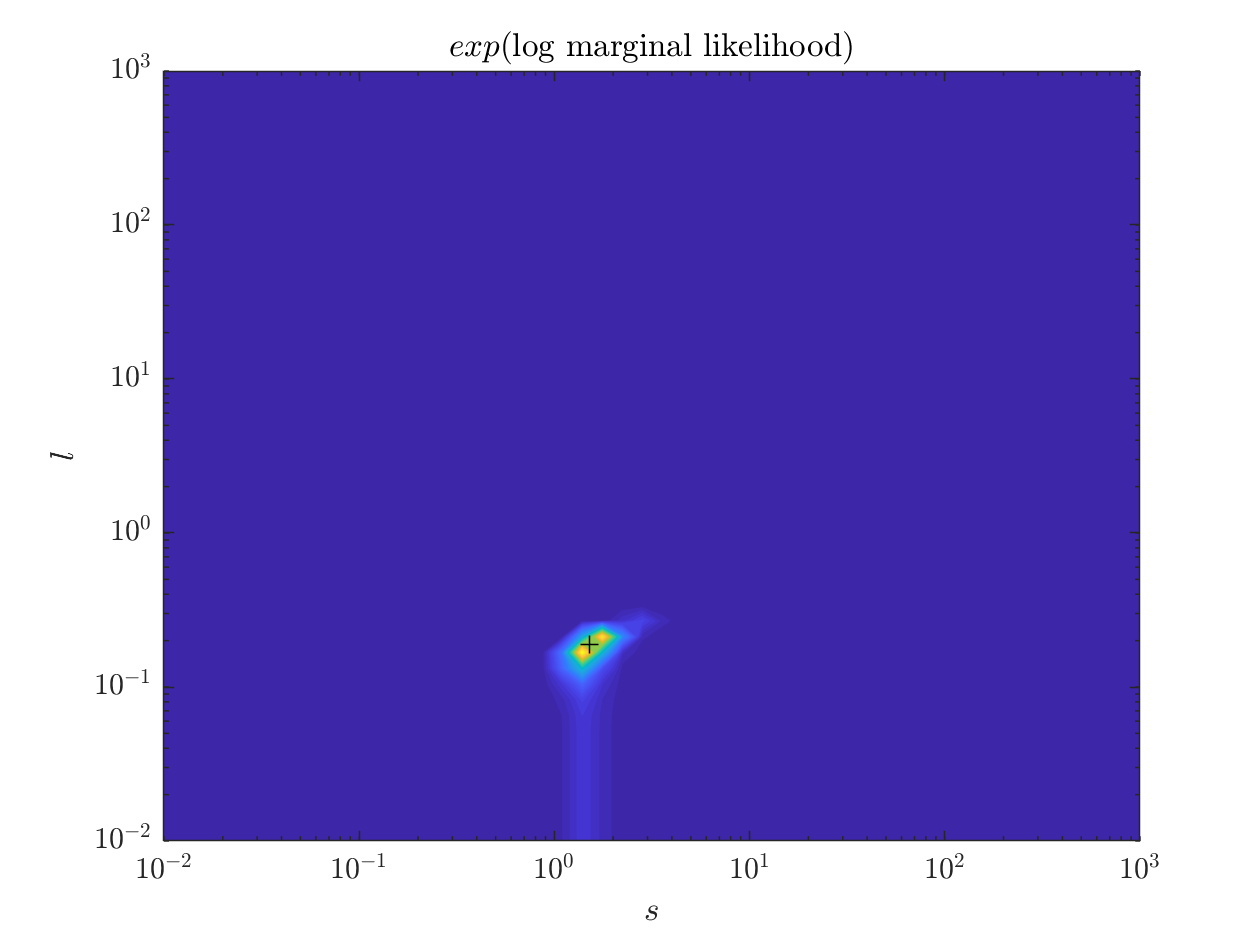

%%perform a sweep over parameters:
[S,L] = meshgrid(logspace(-2,3,50),logspace(-2,3,50)); Lml = L ;
for ind1 = 1:length(S)
    for ind2 = 1:length(S)
        Lml(ind1,ind2) = log_marginal_likelihood(log(S(ind1,ind2)),log(L(ind1,ind2)),log(i0),kernel_fun,x_data,y_data);
    end
end
figure()
contourf(S,L,exp(Lml),50,'linecolor','flat'); hold on;
plot(s,l,'k+')
title('$exp(\textrm{log marginal likelihood})$','Interpreter','latex')
xlabel('$s$','Interpreter','latex'); ylabel('$l$','Interpreter','latex');
set(gca,'yscale','log','xscale','log')

## Bayesian Optimization for GPR

- Discuss why it's needed, where it's used, how it compares to other methods

- Discuss the algorithm

- Discuss choice of acquisition functions

Gaussian process regression gives an interpolant for the data sampled and uncertainty for that interpolant. Here, we will name the samples $\mathbf{x}_{i}$ and the measurements or data as $y_{i} = f(\mathbf{x}_{i})$.Sometimes sampling the data (computing $f$) can be very expensive. For example, say you are testing optimal angle of attacks. Running an experiment can be time consuming  as each iteration requires the geometry to be changed. Running a simulation is just as bad because you'll have to create a new grid and recompute the simulation. The idea here is that each time you tested a parameter $\mathbf{x}_{i}$, you get data $y_{i}$. Then we will use the GPR model to let us know what are the next parameters to try. The goal is to choose the next points to get the largest value of $y_{i}$, i.e. the optimal $\mathbf{x}_{s}$.   

There are many options for optimizing these sorts of problems. Newton's method or gradient descent is one option, but it requires information on the derivatives and can sometimes make incremental steps. Furthermore, it might get stuck at a local maxima with these options. Other options are related to convex optimization, but as the name implies, requires $f$ to be convex. This may not be the case in general applications. As a result, we will treat $f$ as a black box and seek for a gradient-free method to sample our parameter space. 

Here we will define two concepts, **exploration** and **exploitation.** **Exploration** means that we search the parameter space to look at regions we have not sampled yet. Some algorithms randomly search other regions in case they are getting stuck in a local maxima. In Bayesian optimization we use the uncertainty from the GPR to search the space. **Exploitation** means that if we have knowledge that we're in a local maxima region then we should keep sampling in this region. Gradient descent would give small increments because $\nabla f$ is small near the local maxima and moves in the direction where $\nabla f$ decreases. In Bayesian optimization, the exploitation would take the form of the interpolant. 

**How does the Bayesian optimization weigh the exploration and exploitation? **This is done by using the **acquisition function. **

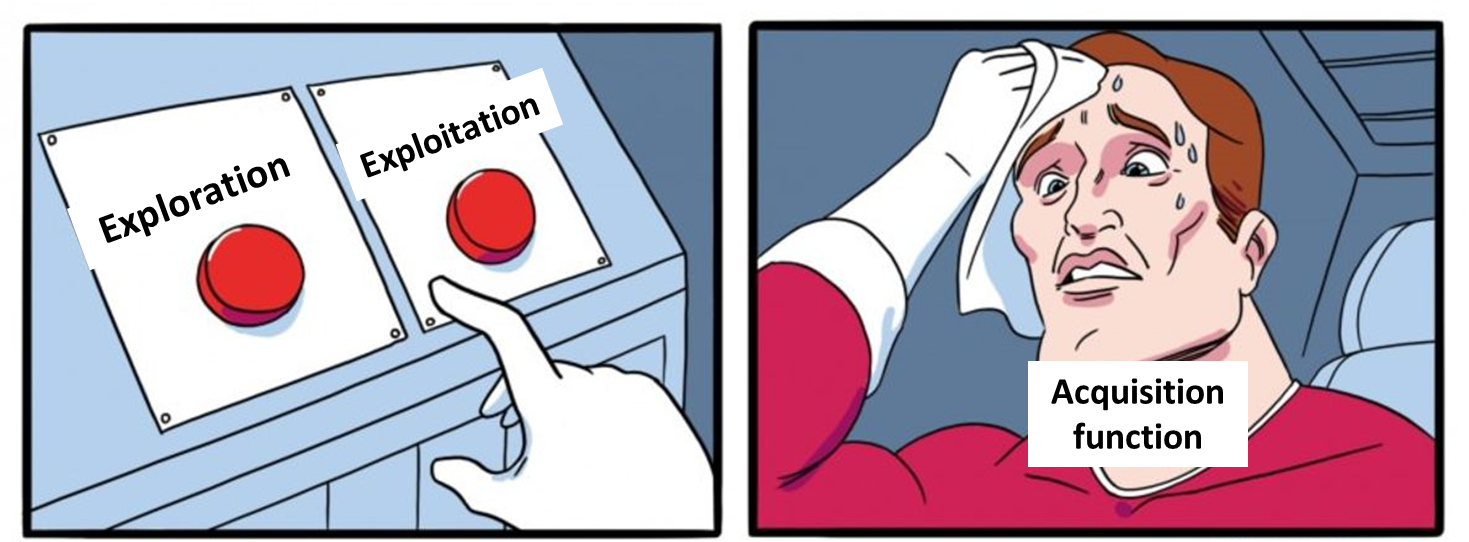

The acquisition function $a$ is a function of the uncertainty $\mu$ and the interpolant $m$ from the GPR s.t. 


$$a(\mathbf{x};\mu,m) = h(\mu(\mathbf{x}),m(\mathbf{x}))$$


where $h$ is chosen depending on the strategy one wishes to use for the Bayesian optimization. The next point to sample would then be 


$$\mathbf{x}_{s} = \textrm{argmax}_\mathbf{x}(a(\mathbf{x};\mu,m)$$


Determining the next point involves only the GPR that was done on the previously sampled points! 

**Common acquisition function choices**

***1) Upper confidence bound**** -* This is the simplest and most straight forward acquisition function. Here


$$a = m + \lambda \mu$$


In this case, the parameter $\lambda$ balances the exploration and exploitation. It samples points where the interpolant plus its predicted uncertainty are largest. A large value for $\lambda$ means more exploration while a small value of $\lambda$ means more exploitation. 

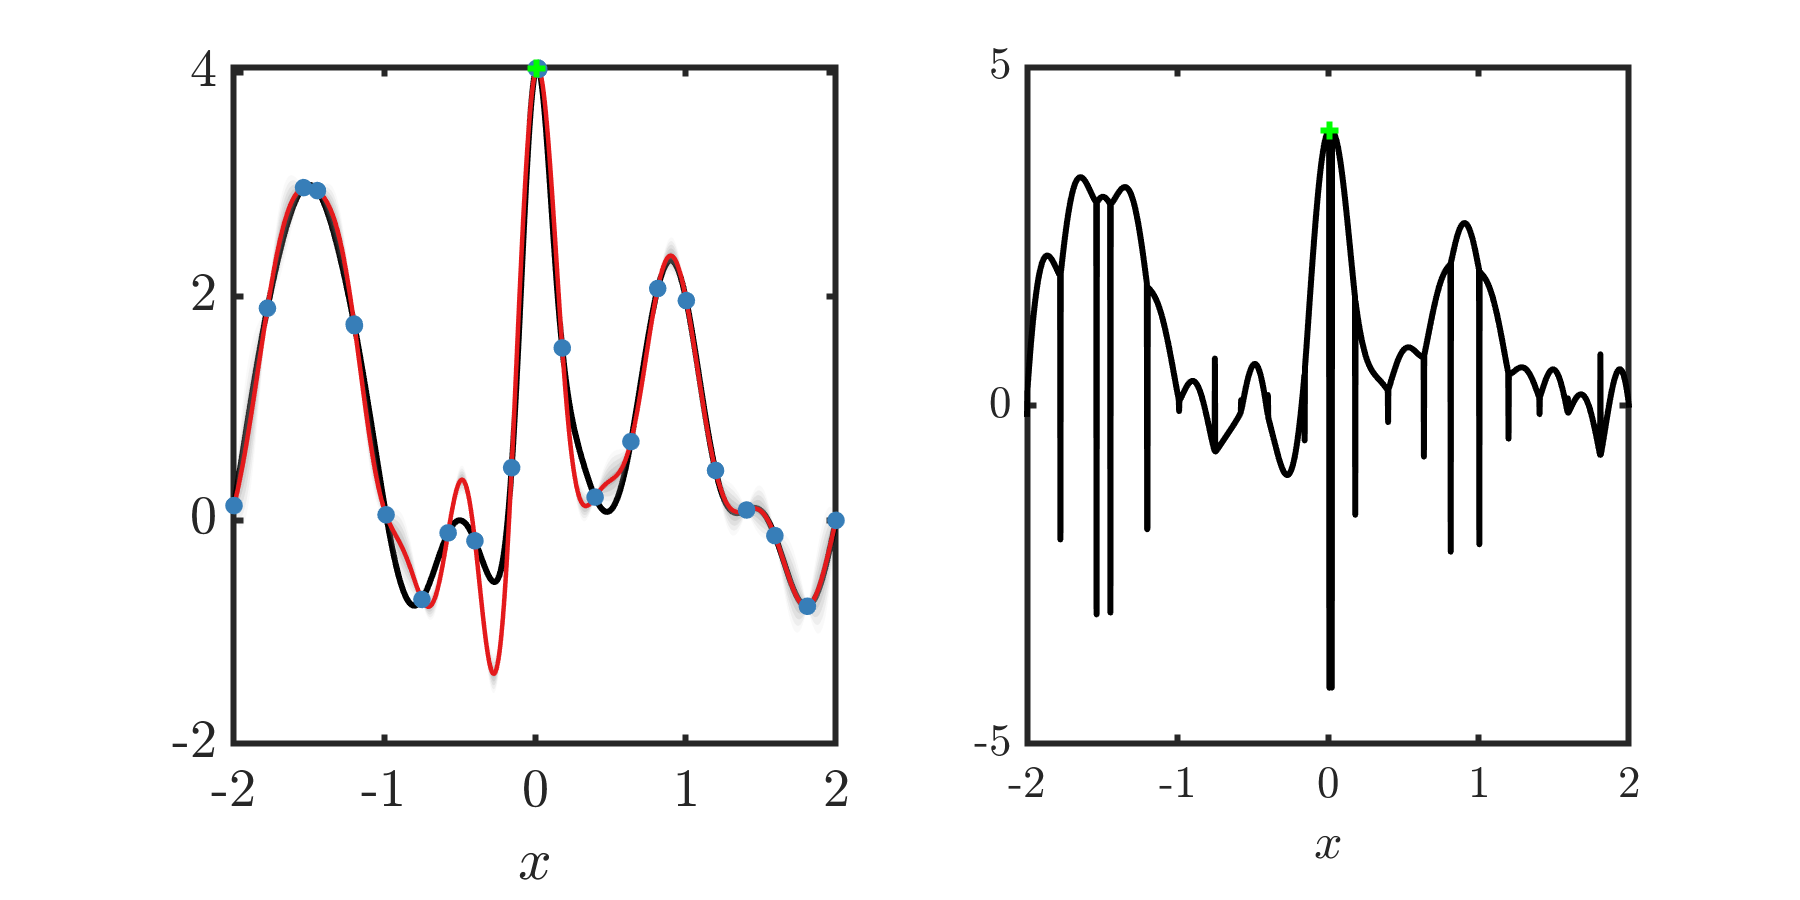

clear all; close all; clc;
rng(1)
x = linspace(-2,2,2000)';
kernel_fun = @(x1,x2,s,l) s.^2.*exp(-(x1-x2).^2./(2*l.^2)); %radial basis function;
%function we wish to maximize:
f = @(x) sin(2*pi*x).*sin(1*pi*(x+.5)) + 2*exp(-(x-1).^2/(2*.2^2)) + 3*exp(-(x+1.5).^2/(2*.2^2)) + 4*exp(-(x).^2/(2*.1.^2));
ii = round(linspace(1,length(x),6))';  %equispaced initial sampling
%ii = randperm(length(x)); ii = ii(1:6); %nonuniform initial sampling
x0 = x(ii(:)); %initial sampling of the parameter space
y0 = f(x0); %initial points
s  = 3; l = .5; i = 10^-6;
%get the optimal parameters with the initial points:
[s,l,i] = parameter_optimization(kernel_fun,x0,y0,2,.1);
figure()
for ind = 1:20
    subplot(1,2,1)
    plot(x,f(x),'k','LineWidth',2); hold on;
    [m, cov_m, mu] = plot_results(x0,y0,x,s,l,i,kernel_fun,0); u = sqrt(abs(mu));
    xlabel('$x$','Interpreter','latex'); xticks([-2:2])
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%ACQUISITION FUNCTION DEFINITION%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    Lf             = 10; %parameter weighing the exploration and exploitation
    a              = m + Lf*u; %acquisition function
    Mask           = ones(size(x));
    for ind1 = 1:length(x0)
        Mask(x==x0(ind1)) = min(a);
    end
    a              = Mask.*a; %set points already sampled to smallest value.
    [~,index]      = max(a);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%ACQUISITION FUNCTION DEFINITION%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    hold on;
    plot(x(index),m(index),'g+','LineWidth',2)
    hold off
    subplot(1,2,2)
    plot(x,a,'k','linewidth',2)
    hold on;
    plot(x(index),a(index),'g+','LineWidth',2)
    hold off
    if sum(x0==x(index))==0
    else
        disp('Testing same point!')
    end
    x0(end+1) = x(index); %update the new values
    y0(end+1) = f(x(index)); %update the new samples
    xlabel('$x$','Interpreter','latex'); xticks([-2:2])
    set(gca,'linewidth',2,'fontsize',15)
    set(gcf,'position',[100,100,800,400])
    pause(.5)
    [s,l,i] = parameter_optimization(kernel_fun,x0,y0,s,l); %optimize the next parameters
end

Note that **if we didn't mask the already sampled points**, there would be **nothing** to keep the acquisition function from **sampling the same points** or **nearby points**. This causes either $K$ to be ill condiitoned or even non-invertible and *freezes *the updates. That is, there's no improvement if we keep sampling the same point over and over again! 

***2) Probability of improvement**** - *Suppose from out current calculation we've found $y^*$ as the maximum value. We can define an improvement as 


$$I(\mathbf{x}) = \max(f(\mathbf{x}) - y^{*},0)$$


So its only nonnegative if $f(\mathbf{x})>y^{*}$. We model $f(\mathbf{x})$ as a Gaussian process with distribution $\mathcal{N}(m,\mu)$ so $f(\mathbf{x}) = m(\mathbf{x}) + z\mu(\mathbf{x})$ with $z \in \mathcal{N}(0,1)$. We can define the probability that $I(\mathbf{x})\gt 0$ as $P_{I}(\mathbf{x})$. Since this was parameterized by $z$, this is equivalent to to finding the probability that $z>z_{0} = -\frac{m(\mathbf{x}) - y^{*}}{\mu(\mathbf{x})}$ This is given by the cumulative distributive function, $\Phi$, as

   
$$P_{I}(\mathbf{x}) = 1-\Phi(z_0) = \Phi(-z_{0}) = \Phi\left(\frac{m(\mathbf{x}) - y^{*}}{\mu(\mathbf{x})}\right)$$


In this case, the acquisition function would be $a = P_{l}(\mathbf{x})$. From the code below, we can see that $\Phi(z)$ is greatest for increasing $z$ and decreases with deacreasing $z$. As a result, when $m(\mathbf{x})>y^{*}$, we expect $a(\mathbf{x})$ to be large, so this considers exploitation. Exploration is only considered when large values of $\mu(\mathbf{x})$ are present if $m(\mathbf{x})<y^{*}$, since this would drive the argument of $\Phi$ to $0$. However, the emphasis on this method is exploitation!

*Note for a probability distribution function *$p(x)$*, *$\Phi(x) = \int_{-\infty}^{x}p(x')dx'$* and *$p(x) = p(-x)$* for an even distribution, such as a normal distribution.*

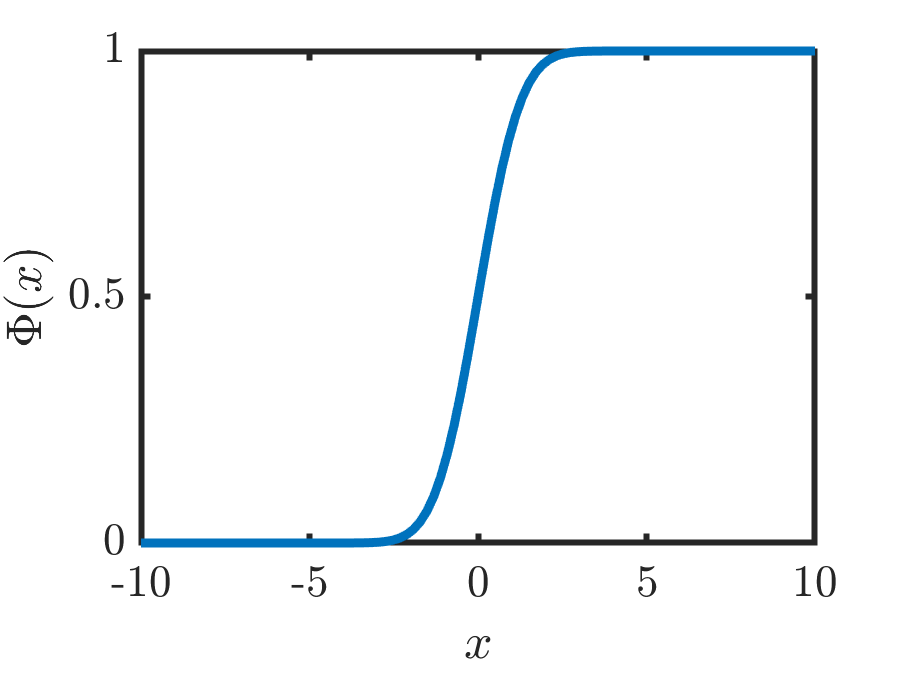

x = linspace(-10,10,100);
figure();plot(x,normcdf(x),'LineWidth',3); %normcdf creates \Phi, assuming a normal distribution (N(0,1))
xlabel('$x$','Interpreter','latex'); ylabel('$\Phi(x)$','Interpreter','latex'); %axis tight;
set(gca,'linewidth',2,'fontsize',15)
set(gcf,'position',[100,100,400,300])

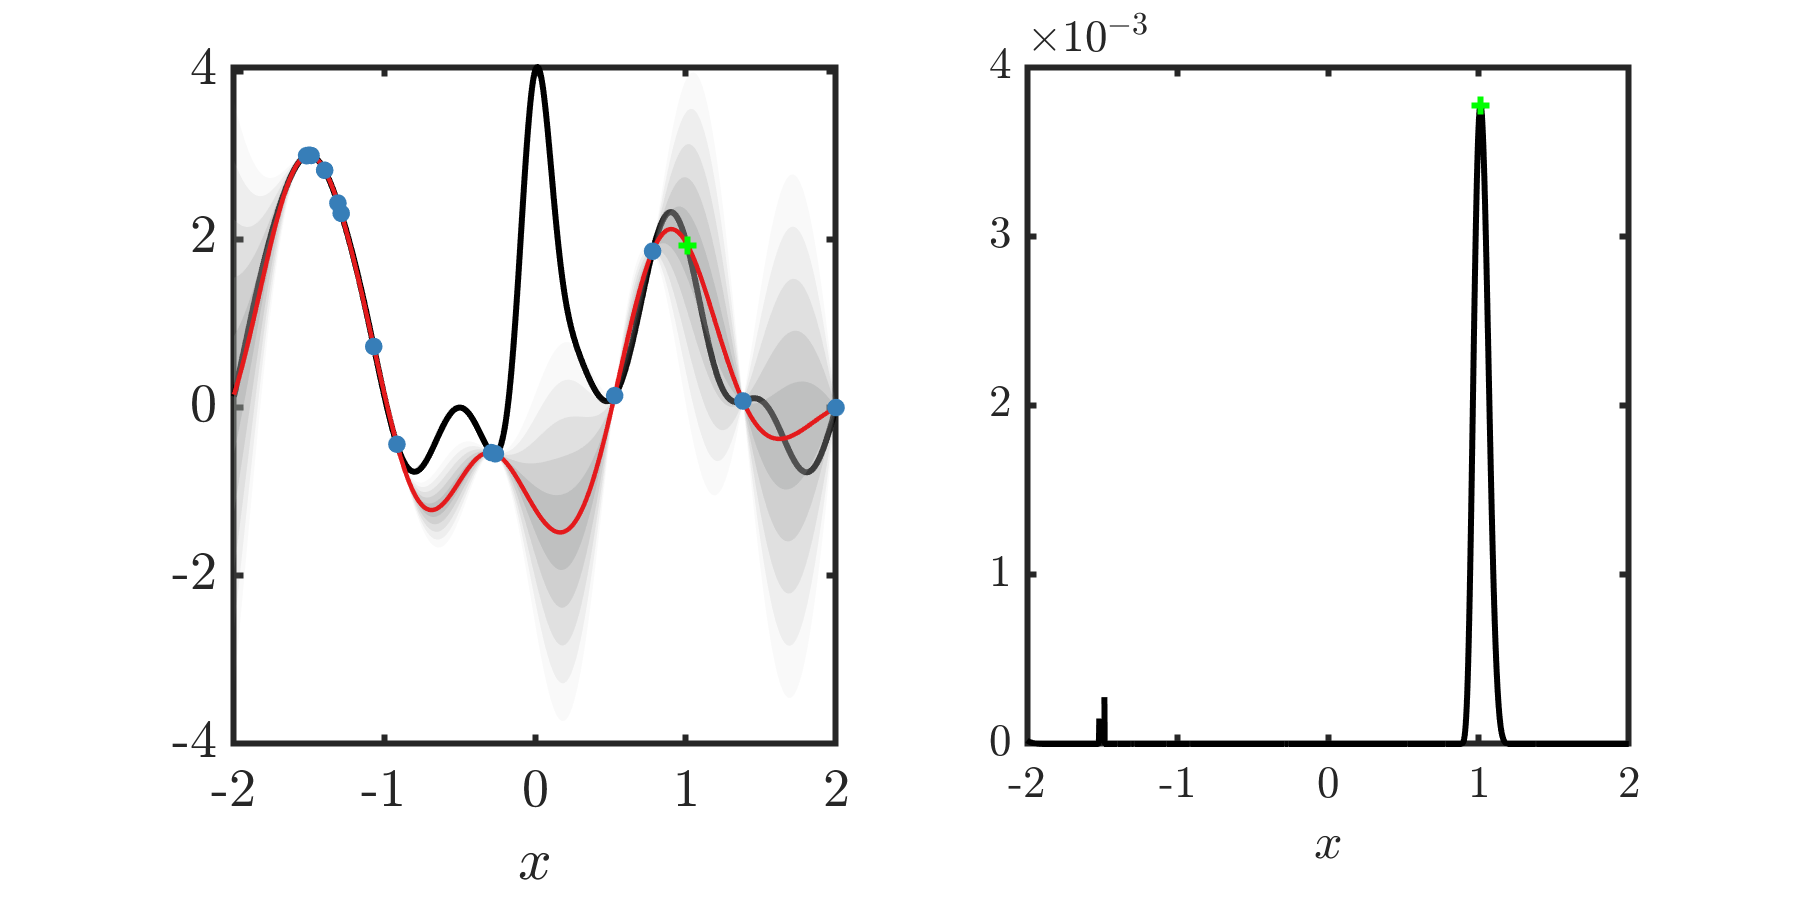

clear all; close all; clc;
rng(2)
x = linspace(-2,2,2000)';
kernel_fun = @(x1,x2,s,l) s.^2.*exp(-(x1-x2).^2./(2*l.^2)); %radial basis function;
%function we wish to maximize:
f = @(x) sin(2*pi*x).*sin(1*pi*(x+.5)) + 2*exp(-(x-1).^2/(2*.2^2)) + 3*exp(-(x+1.5).^2/(2*.2^2)) + 4*exp(-(x).^2/(2*.1.^2));
ii = round(linspace(1,length(x),6))';  %equispaced initial sampling
ii = randperm(length(x)); ii = ii(1:6); %nonuniform initial sampling
x0 = x(ii(:)); %initial sampling of the parameter space
y0 = f(x0); %initial points
s  = 3; l = .5; i = 10^-9;
%get the optimal parameters with the initial points:
[s,l,i] = parameter_optimization(kernel_fun,x0,y0,2,.1);
figure()
for ind = 1:22
    subplot(1,2,1)
    plot(x,f(x),'k','LineWidth',2); hold on;
    [m, cov_m, mu] = plot_results(x0,y0,x,s,l,i,kernel_fun,0); u = sqrt(abs(mu));
    xlabel('$x$','Interpreter','latex'); xticks([-2:2])
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%ACQUISITION FUNCTION DEFINITION%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    ystar          = max(m); %get the best value;
    argum          = (m - ystar)./(u + 10^-9); %argument of the normcdf
    a              = normcdf(argum); %acquisition function
    Mask           = ones(size(x));
    for ind1 = 1:length(x0)
        Mask(x==x0(ind1)) = nan;
    end
    a              = Mask.*a; %set points already sampled to smallest value.
    [~,index]      = max(a);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%ACQUISITION FUNCTION DEFINITION%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    hold on;
    plot(x(index),m(index),'g+','LineWidth',2)
    hold off
    subplot(1,2,2)
    plot(x,a,'k','linewidth',2)
    hold on;
    plot(x(index),a(index),'g+','LineWidth',2)
    hold off
    if sum(x0==x(index))==0
    else
        disp('Testing same point!')
    end
    x0(end+1) = x(index); %update the new values
    y0(end+1) = f(x(index)); %update the new samples
    xlabel('$x$','Interpreter','latex'); xticks([-2:2])
    set(gca,'linewidth',2,'fontsize',15)
    set(gcf,'position',[100,100,800,400])
    pause(.1)
    [s,l,i] = parameter_optimization(kernel_fun,x0,y0,s,l); %optimize the next parameters
end

Note that this one does less exploration than the previous one. It gets stuck near certain peaks and takes a lot of work for it to look into other regions. 

***3) Expected Improvement**** - *The latter strategy looks at the probability of improving the current guess but it does not incorporate any magnitude information. For this we need to consider the expected improvement:


$$\mathbb{E}(\mathbf{x}) = \int_{\infty}^{\infty}I(\mathbf{x})\phi(z)dz$$


where $z$ is defined as before and $\phi(z) = \frac{1}{\sqrt{2\pi}}\exp(-z^{2}/2)$, the pdf of the normal distribution. We saw before that $I(\mathbf{x}) = \max(f(\mathbf{x}) - y^{*},0)$ is nonzero only if $z\ge z_{0}$, so the integral becomes


$$\mathbb{E}(\mathbf{x}) = \int_{z_{0}}^{\infty}I(\mathbf{x})\phi(z)dz =  \int_{z_{0}}^{\infty}(m + z\mu - y^*)\phi(z)dz$$


We can carry out these integrations and find that we get 


$$\mathbb{E}(\mathbf{x}) = (m -y^*)\Phi\left(-z_{0}\right) + \mu\phi\left(z_{0}\right)$$



$$\mathbb{E}(\mathbf{x}) = (m(\mathbf{x}) -y^*)\Phi\left(\frac{m (\mathbf{x})- y^*}{\mu(\mathbf{x})}\right) + \mu(\mathbf{x})\phi\left(\frac{m(\mathbf{x}) - y^*}{\mu(\mathbf{x})}\right)$$


So our acquisition function would then be $a = \mathbb{E}(\mathbf{x})$. This quantity is large when $m(\mathbf{x})>y^{*}$ or when $\mu(\mathbf{x})$is large. The first term dictates the exploitation, the second term dicates the exploration. 

The acquisition function can also incorporate a hyperparameter. In this case, the hyperparameter $\gamma$ is used to augment $y^{*}$ as follows:


$$\mathbb{E}(\mathbf{x}) = (m(\mathbf{x}) -y^*-\gamma)\Phi\left(\frac{m (\mathbf{x})- y^*-\gamma}{\mu(\mathbf{x})}\right) + \mu(\mathbf{x})\phi\left(\frac{m(\mathbf{x}) - y^*-\gamma}{\mu(\mathbf{x})}\right)$$


$\gamma$ makes the perceived value of $y^{*|$ to be larger. As a result, the acquistion function needs to focus on exploration more when $\gamma$ increases. 

There are many choices of acquisition functions that one could choose. These are only the tip of the iceberg. Depending on **your** application, **your** choice of acquisition function may differ!

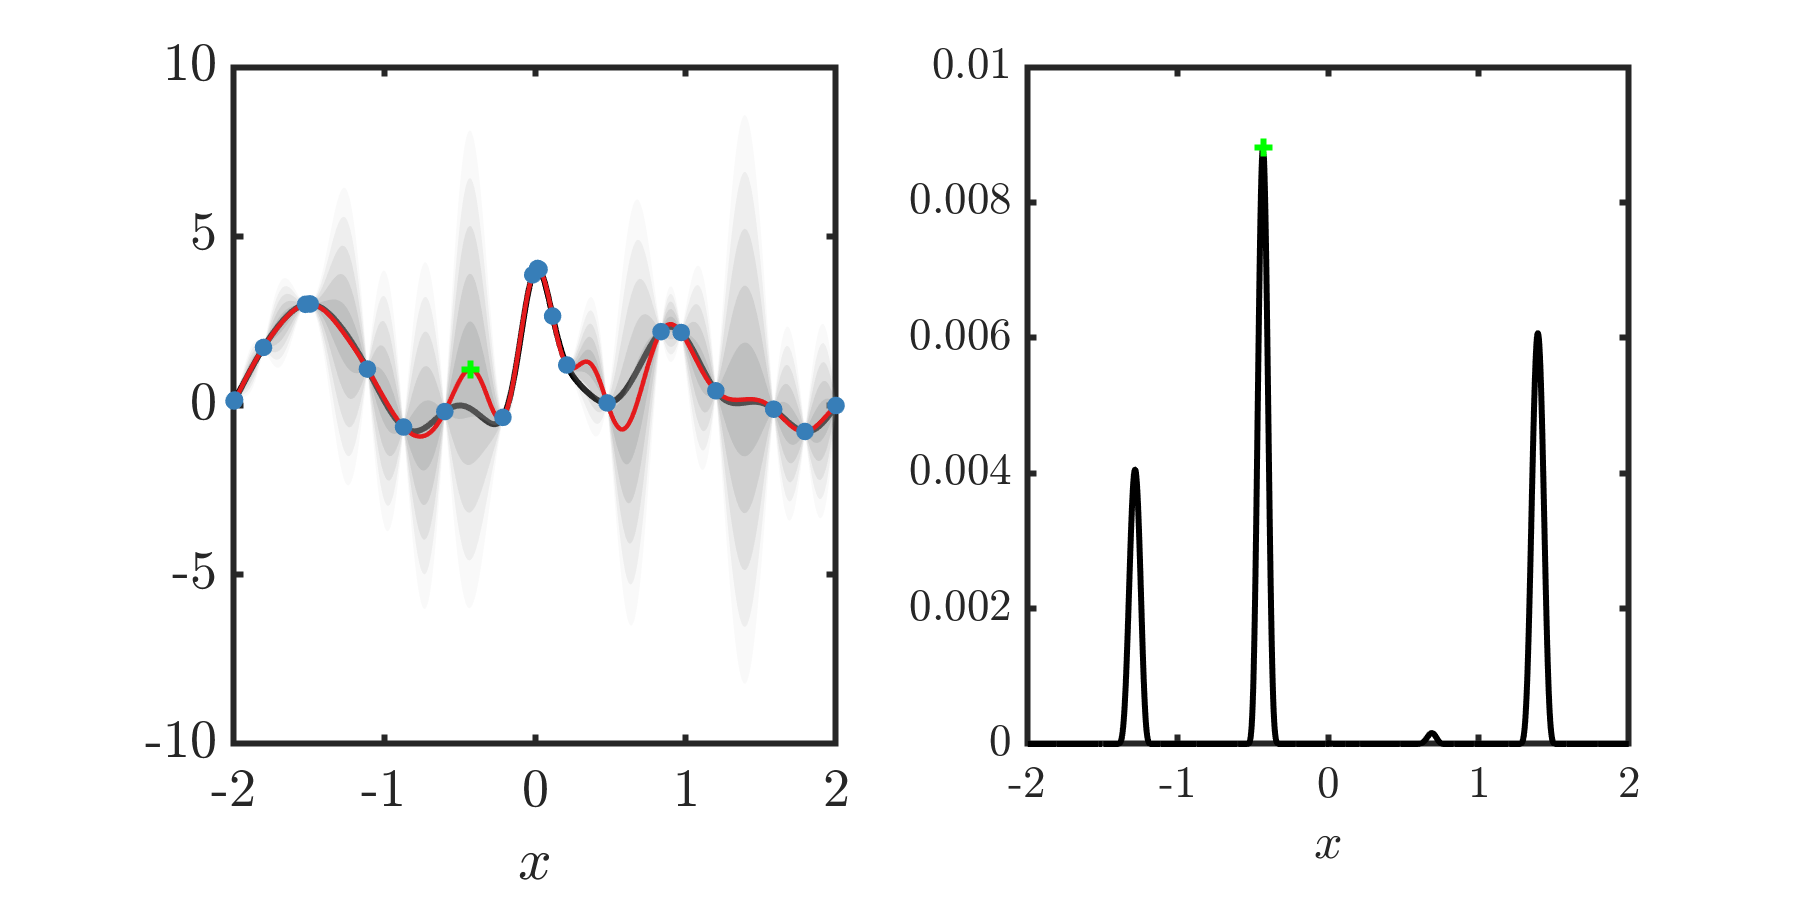

clear all; close all; clc;
rng(1)
x = linspace(-2,2,2000)';
kernel_fun = @(x1,x2,s,l) s.^2.*exp(-(x1-x2).^2./(2*l.^2)); %radial basis function;
%function we wish to maximize:
f = @(x) sin(2*pi*x).*sin(1*pi*(x+.5)) + 2*exp(-(x-1).^2/(2*.2^2)) + 3*exp(-(x+1.5).^2/(2*.2^2)) + 4*exp(-(x).^2/(2*.1.^2));
ii = round(linspace(1,length(x),6))';  %equispaced initial sampling
ii = randperm(length(x)); ii = ii(1:6); %nonuniform initial sampling
x0 = x(ii(:)); %initial sampling of the parameter space
y0 = f(x0); %initial points
s  = 3; l = .5; i = 10^-9;
%get the optimal parameters with the initial points:
[s,l,i] = parameter_optimization(kernel_fun,x0,y0,2,.1);
figure()
for ind = 1:20
    subplot(1,2,1)
    plot(x,f(x),'k','LineWidth',2); hold on;
    [m, cov_m, mu] = plot_results(x0,y0,x,2*s,l,i,kernel_fun,0); u = sqrt(abs(mu));
    xlabel('$x$','Interpreter','latex'); xticks([-2:2])
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%ACQUISITION FUNCTION DEFINITION%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    gamma          = .001; %parameter governing exporation and exploitation
    ystar          = max(y0); %get the best value;
    phi            = @(x) 1/sqrt(2*pi)*(exp(-x.^2/2)); %the probability distribution function
    argum          = (m - ystar - gamma)./(u + 10^-9); %argument of the normcdf
    a              = (m - ystar - gamma).*normcdf(argum) + u.*phi(argum); %acquisition function
    Mask           = ones(size(x));
    for ind1 = 1:length(x0)
        Mask(x==x0(ind1)) = nan;
    end
    a              = Mask.*a; %set points already sampled to smallest value.
    [~,index]      = max(a);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%ACQUISITION FUNCTION DEFINITION%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    hold on;
    plot(x(index),m(index),'g+','LineWidth',2)
    hold off
    subplot(1,2,2)
    plot(x,a,'k','linewidth',2)
    hold on;
    plot(x(index),a(index),'g+','LineWidth',2)
    hold off
    if sum(x0==x(index))==0
    else
        disp('Testing same point!')
    end
    x0(end+1) = x(index); %update the new values
    y0(end+1) = f(x(index)); %update the new samples
    xlabel('$x$','Interpreter','latex'); xticks([-2:2])
    set(gca,'linewidth',2,'fontsize',15)
    set(gcf,'position',[100,100,800,400])
    pause(.1)
    [s,l,i] = parameter_optimization(kernel_fun,x0,y0,s,l); %optimize the next parameters
end

By including the parameter gamma, you are able to perform more exploration!

## Further Reading and Helpful Tools: 

Our goal with this tutorial was to show you the main ideas behind Gaussian Process Regression, Kernel functions, Identifying hyperparameters, and Bayesian Optimization. Our goal was not to build a robust or optimized GPR or Bayesian Optimization code. Our goal was to introduce you to the concepts that are used by existing libraries. In practice, one would use said libraries that handle many of these implementations in more stable and computationally efficient methods with many more features. Here are some helpful resources for existing libraries: 

**On MATLAB: **

- Gaussian process regression can be done through fitgpr. More information can be found in this link: [https://www.mathworks.com/help/stats/gaussian-process-regression-models.html](https://www.mathworks.com/help/stats/gaussian-process-regression-models.html) 

- Bayesian optimization can be done through here [https://www.mathworks.com/help/stats/bayesian-optimization-workflow.html](https://www.mathworks.com/help/stats/bayesian-optimization-workflow.html)

- Very intuitive Github repository for using GPR with derivative information [https://github.com/erichanslee/GP_Derivatives](https://github.com/erichanslee/GP_Derivatives) 

- [https://gaussianprocess.org/gpml/code/matlab/doc/](https://gaussianprocess.org/gpml/code/matlab/doc/) 

**On Python:**

- The scikitlearn library has many of these functions in their module : [https://scikit-learn.org/stable/modules/gaussian_process.html](https://scikit-learn.org/stable/modules/gaussian_process.html)

- gpflow [https://gpflow.org/](https://gpflow.org/) 

**If you want to read more: **

- [https://gaussianprocess.org/](https://gaussianprocess.org/) - useful resources and a free textbook on Gaussian Process Regression/Bayesian Optimization

- [https://arxiv.org/abs/2009.10862](https://arxiv.org/abs/2009.10862) - An Intuitive Tutorial to Gaussian Processes Regression

- [https://arxiv.org/abs/1807.02811](https://arxiv.org/abs/1807.02811) - A Tutorial on Bayesian Optimization

%helper functions:

function [mean_at_values, cov_at_values, var_at_values] = GPR(xdata,ydata,x,s,l,i,kernel_fun)
%set up the kernels
K  = covariance_matrix(xdata,xdata,s,l,kernel_fun);
%the second term models noise and helps regularize the inversion
K = (K + (i^2+10^-5)*diag(ones(length(xdata),1)));
Ki= inv(K); %the inverse
Ks = covariance_matrix(x,xdata,s,l,kernel_fun);
Kss= covariance_matrix(x,x,s,l,kernel_fun);
%get the mean %this is Ks*Ki*y
mean_at_values = Ki*ydata(:);
mean_at_values = Ks*mean_at_values;
%get the covariance
cov_at_values  = Kss - Ks*Ki*(Ks)'; cov_at_values = (cov_at_values + (cov_at_values)')/2 + 0*eps*eye(size(cov_at_values));
%cov_at_values  = Kss - KsKli*KsKli';  cov_at_values = (cov_at_values + (cov_at_values)')/2;
var_at_values  = diag(cov_at_values);
mean_at_values = mean_at_values(1:length(x));
cov_at_values  = cov_at_values(1:length(x));
var_at_values  = var_at_values(1:length(x));
end

function [cov_mat,dcov_matds,dcov_matdl] = covariance_matrix(x1,x2,s,l,kernel_fun)
%covariance matrix without derivative info
cov_mat1 = zeros(length(x1),length(x2));
for ind1 = 1:length(x1)
    for ind2 = 1:length(x2)
        cov_mat1(ind1,ind2) = kernel_fun(x1(ind1),x2(ind2),s,l);
    end
end
cov_mat = cov_mat1;
if nargout>1
    dcov_matds = zeros(length(x1),length(x2));
    dcov_matdl = dcov_matds;
    for ind1 = 1:length(x1)
        for ind2 = 1:length(x2)
            dcov_matds(ind1,ind2) = 2*kernel_fun(x1(ind1),x2(ind2),s,l)./s;
            dcov_matdl(ind1,ind2) = 1*kernel_fun(x1(ind1),x2(ind2),s,l).*(x1(ind1)-x2(ind2)).^2./l.^3;
        end
    end
end
end

function [LML] = log_marginal_likelihood(s,l,i,kernel_fun,xdata,ydata)
%input parameters s,l,i are in log values.
s = exp(s); l = exp(l); i = exp(i);
[K]       = covariance_matrix(xdata,xdata,s,l,kernel_fun); %create the covariance matrix
K         = (K + (i+10^-8)*eye(length(K))); %for the inversion, adding noise and regularizer (10^-9)
Ki        = inv(K);
alpha     = Ki*ydata(:);
term1     = ydata(:)'*alpha; % This is y'*((K+iI)\y)
term2     = log(det(K)); % This is log(det(K))
LML       = -0.5*(term1 + term2 + length(K)*log(2*pi));
end


function [s,l,i] = parameter_optimization(kernel_fun,x_data,y_data,s0,l0)
%create the function to optimize (the log marginal likelihood)
fun = @(X) -(1)*(log_marginal_likelihood(X(1),X(2),10^-10,kernel_fun,x_data,y_data));
%perform the optimization
options = optimoptions('fminunc','Display','off');
Xs = fminunc(fun,[log(s0),log(l0)],options);
s   = exp(Xs(1)); l = exp(Xs(2)); i = 10^-10; %not optimizing over i, assuming this is perfectly known.
end

function [mean_m, cov_m, var_m] = plot_results(x_data,y_data,x,s,l,i,kernel_fun,Np)
%x_data is x locations of samples points, y_data is measurements at sampled points
%x is the data you wish to interpolate onto
%i is the regularizer
%if Np = 0 we are NOT using the periodic kernel. If Np > 0 it is number of
%periods expected in signal
%kernel_fun is the kernel function you want to use, takes in x1 and x2 as arguments
%Does the GPR and plots
if Np == 0
    %change nothing
else
    kernel_fun = @(x1,x2,s,l) kernel_fun(x1,x2,s,l,Np);
end
[mean_m, cov_m, var_m] = GPR(x_data,y_data(1:length(x_data),:),x,s,l,i,kernel_fun);
std_m = sqrt(abs((var_m)));
x2 = [x,flip(x)];
for ind1 = 1:5
    ind = 5-ind1+1;
    top = mean_m + ind*std_m;
    bot = mean_m - ind*std_m;
    inb = ([top;flip(bot)]);
    fill(x2(:),inb(:),[0.5569    0.5686    0.5608],'FaceAlpha',ind1*.05,'EdgeColor','none'); hold on;
end
hold on;
colors = [0.8941    0.1020    0.1098;0.2157    0.4941    0.7216;0.3020    0.6863    0.2902;0.5961    0.3059    0.6392];%cbrewer('qual','Set1',4);%cbrewer('qual','Set1',4);
%plotting:
plot(x,(mean_m),'LineWidth',1.5,'Color',colors(1,:))
hold on;
plot(x_data,(y_data(1:length(x_data))),'.','LineWidth',2,'MarkerSize',20,'Color',colors(2,:))
xlabel('$x$','Interpreter','latex');
set(gca,'LineWidth',2,'FontSize',18)
end